# MEMS Parametric Optimization using LSM and the adjoint formulation

*Example run on a laptop equipped with an Intel(R) Core(TM) Ultra 9 185H CPU @2.50GHz, 32GB RAM @5600MT/s.*

In this example, we tune the nonlinear coefficient of the reduced dynamics on a 3rd-order expansion of the **Lyapunov Subcenter Manifold** (LSM) using parametric optimization (`fmincon`). **Sensitivities** are computed efficiently using the **adjoint method**.

The system we consider is a MEMS gyroscope prototype (named TS4), which is modelled using the **Multi-Point Constraint** (MPC) method: masses are represented by rigid bodies, connected to beams with a master-slave approach. In this demo, we also tune the drive and sense vibration modes to be at specific target frequencies in order to test the mode-tracking algorithm.

References:

- *MEMS model*: Marconi J. et al., "[Exploiting Nonlinearities for Frequency-Matched MEMS Gyroscopes Tuning](https://doi.org/10.1109/INERTIAL51137.2021.9430478)", INERTIAL, 2021*.*

- *LSM Optimization*: Pozzi M., Marconi J., Jain S. & Braghin F., "[Backbone curve tailoring via Lyapunov subcenter manifold optimization](https://doi.org/10.1007/s11071-024-09881-5)", Nonlinear Dynamics, 2024.

- *Adjoint formulation*: Mingwu Li, "[Explicit sensitivity analysis of spectral submanifolds of mechanical systems](https://doi.org/10.1007/s11071-024-09947-4)", Nonlinear Dynamics, 2024.

- *Multi-Point Constraint:* see class `"../src/misc/MultiPointConstraint.m". `For a tutorial, refer to "`../examples/Mechanical/mpc/demo_mpc.mlx`"

clear; close all; clc

addpath ..\..\examples\Mechanical\mpc
run ..\..\startup.m

              _____ _____     
  _   _  __ _|  ___| ____|___ 
 | | | |/ _` | |_  |  _| / __|
 | |_| | (_| |  _| | |__| (__ 
  \__, |\__,_|_|   |_____\___|
  |___/       YetAnotherFEcode




## Model definition (example)

Use the below parameters to change the geometry of the structure. Below, find an example with some random parameters:

p(1) =  20; % delta length (drive beams)
p(2) = -10; % delta length (sense beams)
p(3) = 1;   % delta width (drive beams)
p(4) = 1;   % delta width (sense beams)
p(5) = 0;   % delta width (sense beam connections)

The drive beam shapes are modified from straight lines into a composition of harmonics. Considering for simplicity a beam aligned with the x-axis, the final coordinates become


$$y=y_o +\sum_{k=1}^5 H_k \;\sin \left(\frac{k\pi }{L}x\right)$$


being $y_o$ the original y-coordinates of the beam.

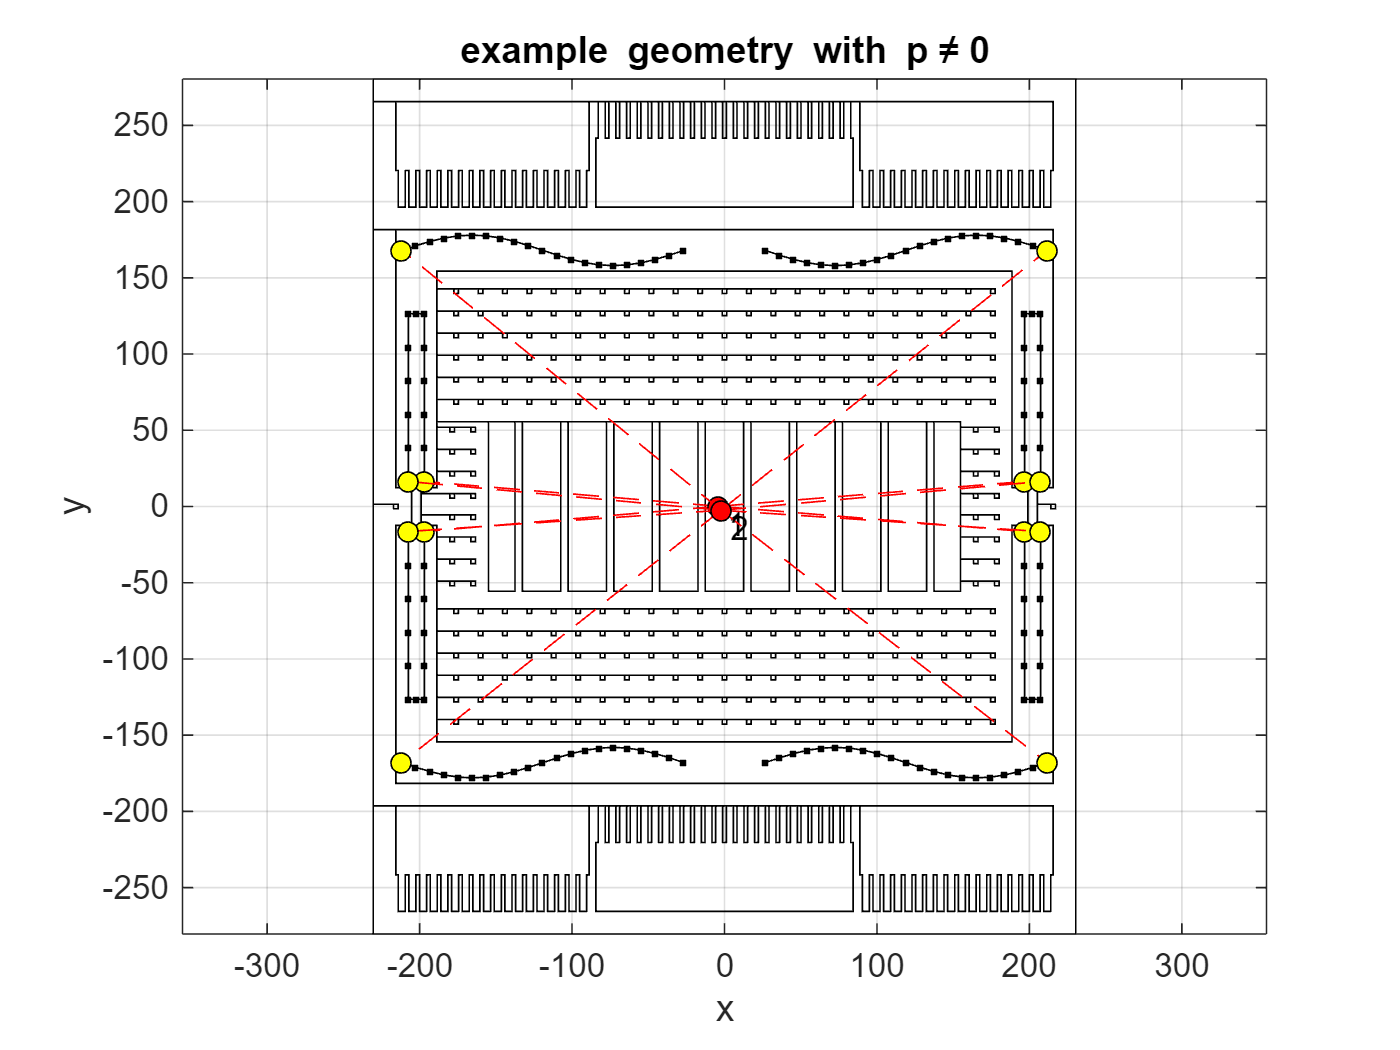

p(6:10)  = [0  10 0 0 0];   % first 5 harmonics for the two TOP drive beams
p(11:15) = [0 -10 0 0 0];   % first 5 harmonics for the two BOTTOM drive beams

obj = build_model(p);
figure
obj.mpc_plot
title('example geometry with p\neq0')

## Preliminary analysis (p=0)

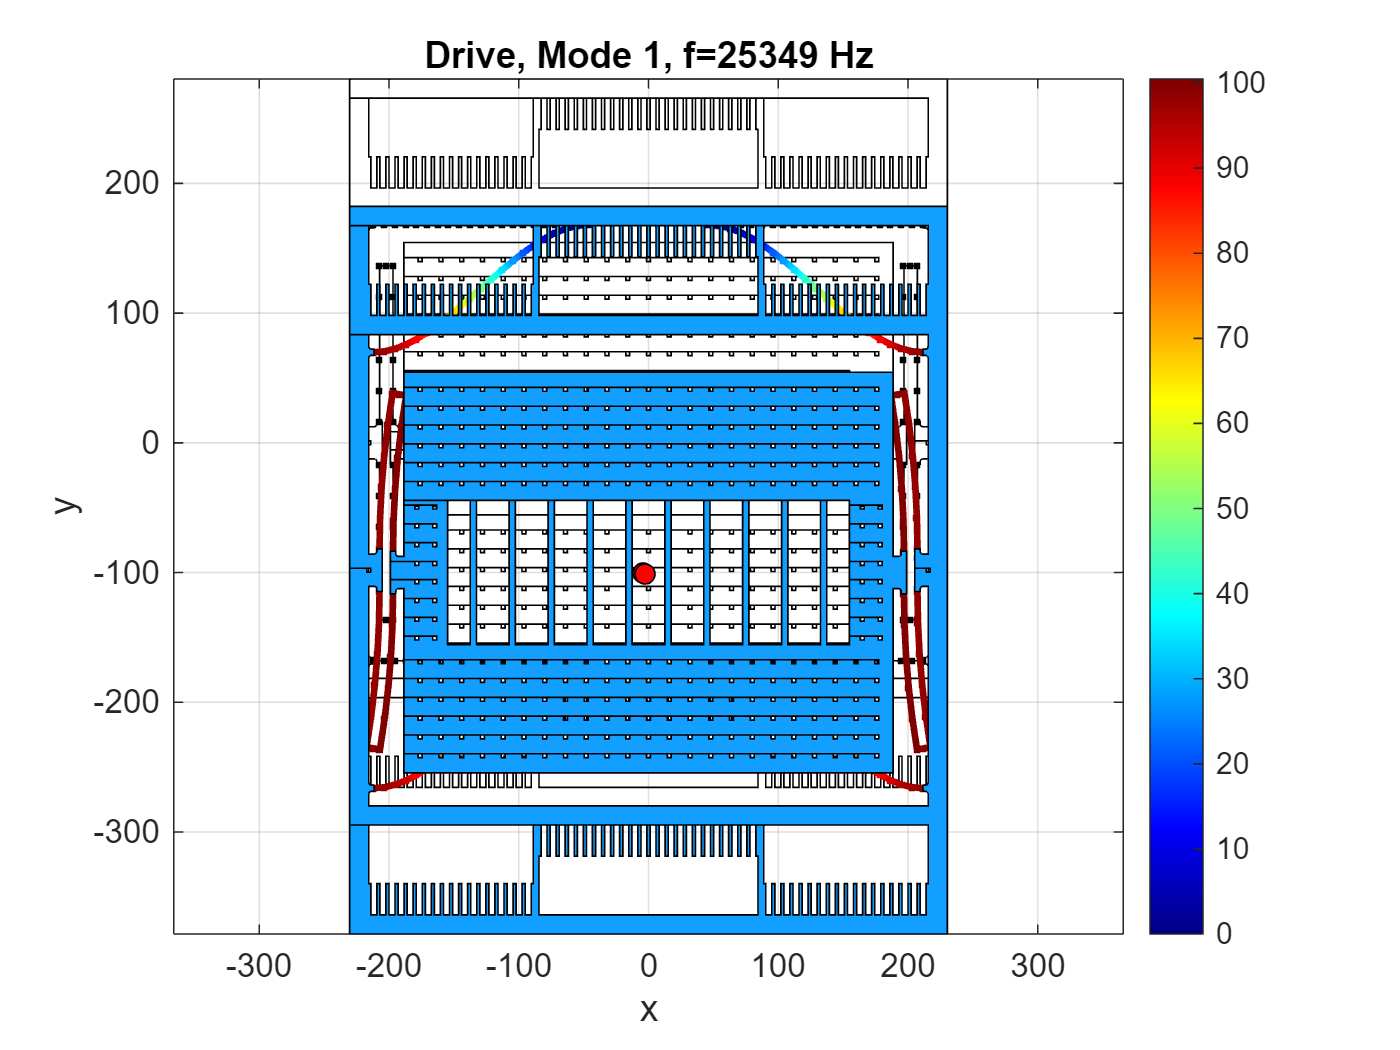

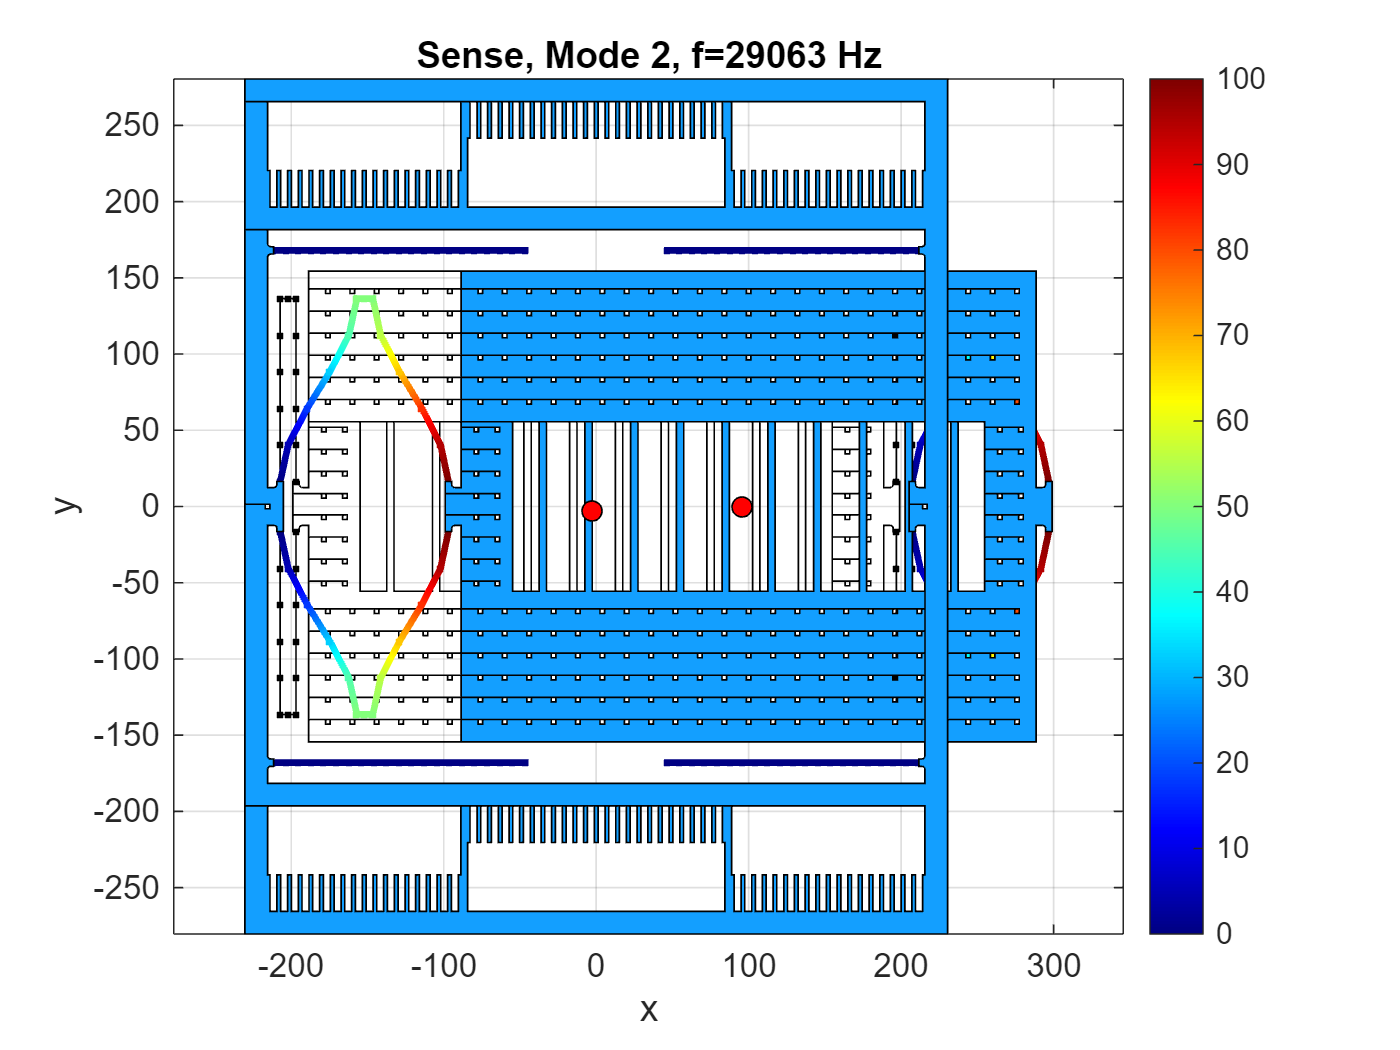

 mode: 1
 dof: 365 
 gamma = 1.32172e+12


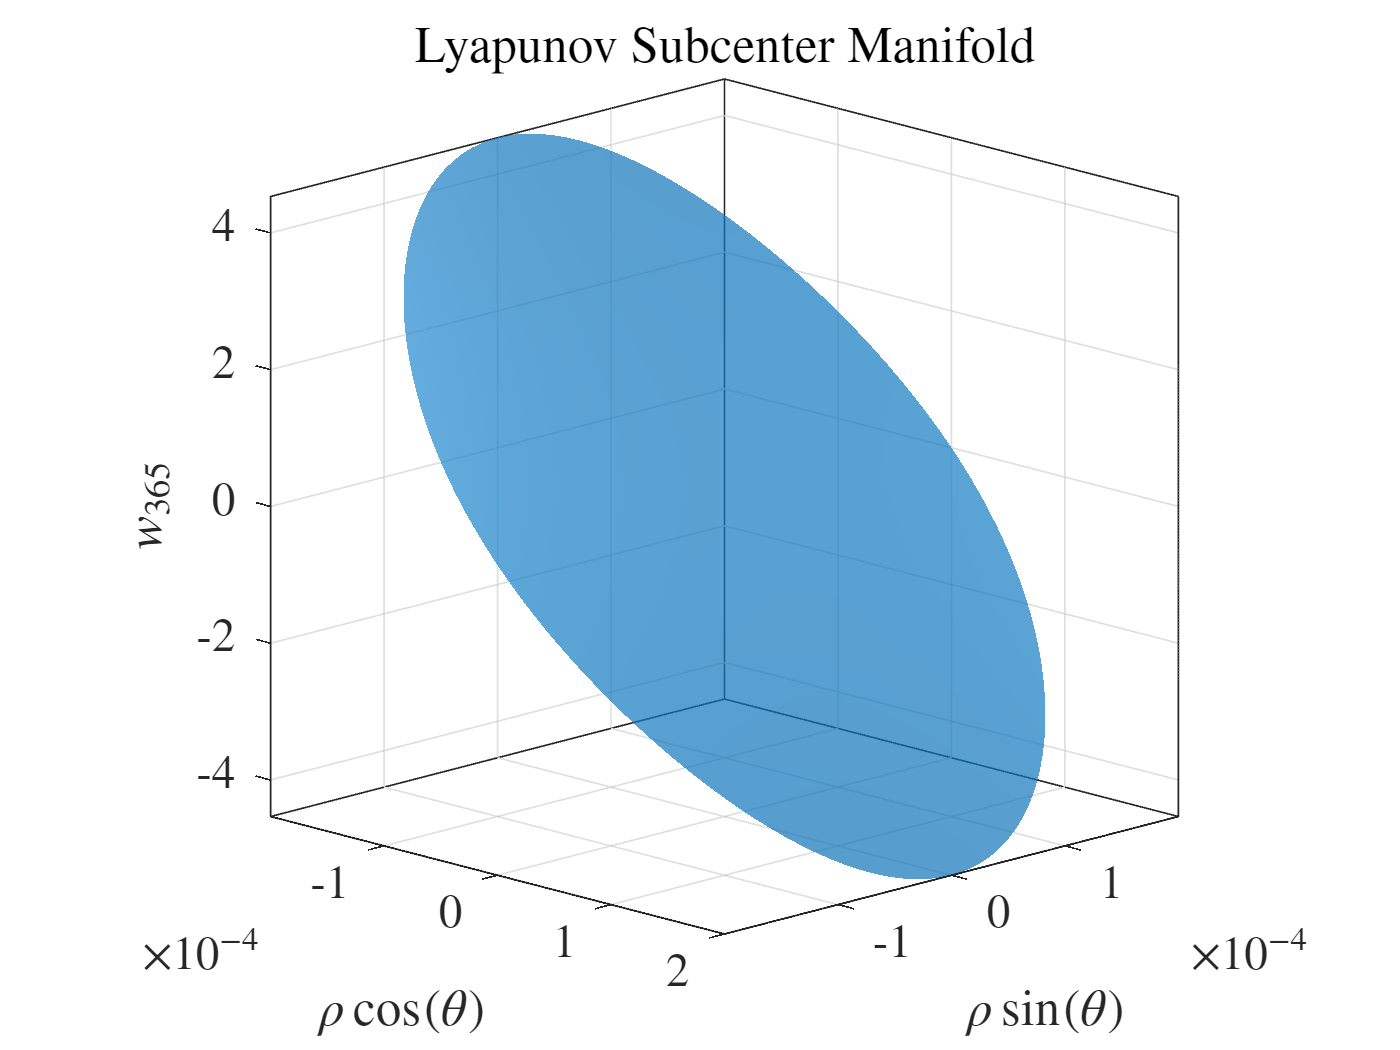

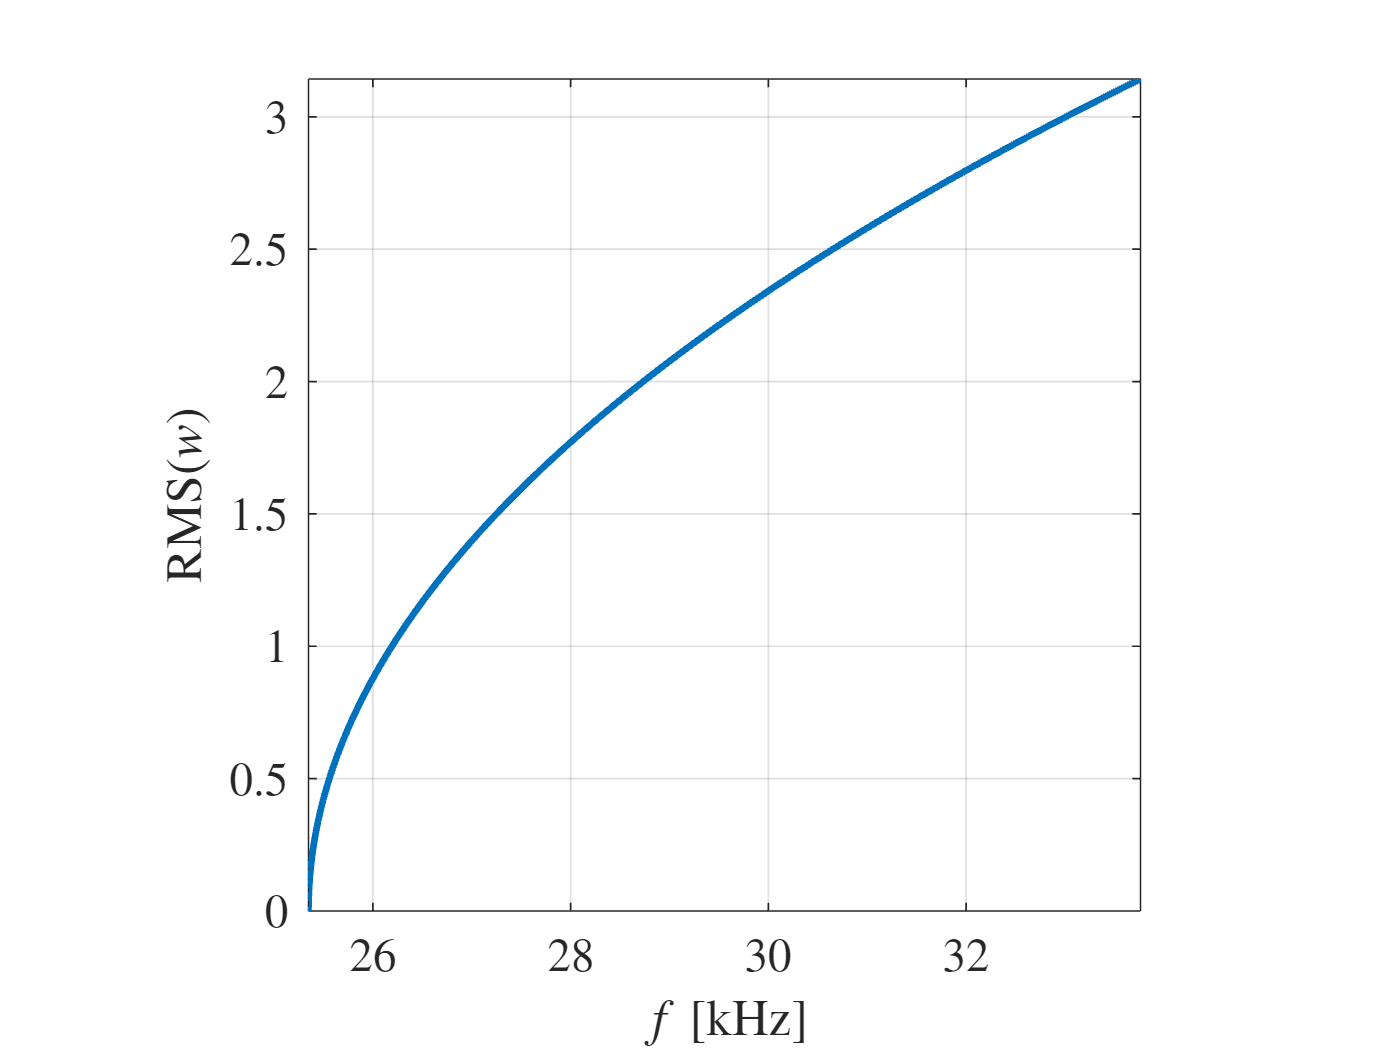

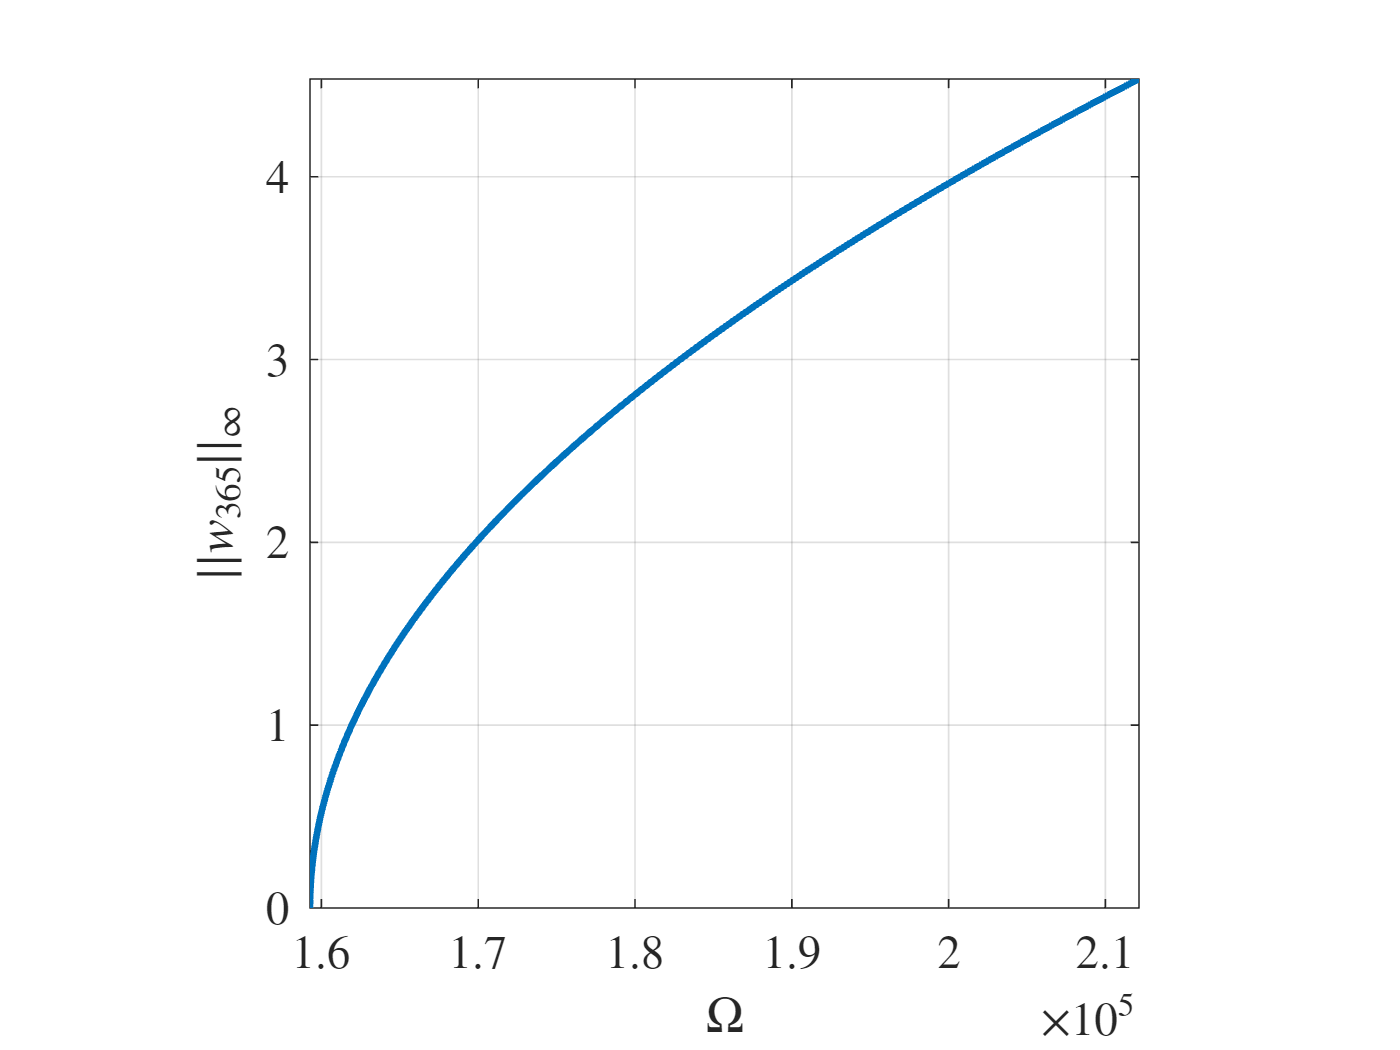

ans = 1.0e+05 *

    1.5927    1.5928    1.5929    1.5932    1.5936    1.5941    1.5947    1.5954    1.5962    1.5971    1.5981    1.5993    1.6005    1.6018    1.6033    1.6049    1.6065    1.6083    1.6102    1.6122    1.6143    1.6165    1.6188    1.6213    1.6238    1.6264    1.6292    1.6320    1.6350    1.6381    1.6413    1.6446    1.6480    1.6515    1.6551    1.6588    1.6626    1.6666    1.6706    1.6748    1.6790    1.6834    1.6879    1.6925    1.6972    1.7020    1.7069    1.7119    1.7170    1.7222


obj = build_model(p*0);
analyze_system(obj)

Last plot can be used to compare the backbone against the result obtained with the SSMtool.

## Parametric optimization

As often required in MEMS resonators, here we tune the structural modes (drive and sense) to specific target frequencies using `fmincon`.

In this example, we also test the **mode-veering** tracking. This allows us to switch drive and sense modes, originally the 1st and 2nd modes for p=0, respectively.

The **optimization problem** is in the following form:


$$\begin{array}{l}
\min_{\mu \;} \;J\\
s\ldotp t\ldotp \;\;{\left(\frac{\omega_d }{\omega {\;}_{d,\textrm{target}} }-1\right)}^2 =0\\
\;\;\;\;\;\;\;\;\;\;{\left(\frac{\omega_s }{\omega {\;}_{s,\textrm{target}} }-1\right)}^2 =0\\
\;\;\;\;\;\;\;\;\;\;\;\;\frac{\gamma }{|\gamma_{\textrm{target}} |}-\textrm{sign}\left(\gamma_{\textrm{target}} \right)<0
\end{array}$$


where $\mu$ is the vector of the design variables, $\omega_{d,s}$ are the drive and sense eigenfrequencies, respectively, and the coefficient $\gamma$ defines the **backbone curve** as:

$\Omega =\omega_o +\gamma \rho^2 +O\left(\rho^3 \right)$,

being $\rho$ the reduced amplitude on the **Lyapunov Subcenter Manifold** (LSM). Finally, being interested only in the constraints, here for simplicity J is set to 0.

The sensitivities for $\gamma$ here are computed *analytically* from the 3rd order LSM (multi-index) expression and using the **adjoint method**. This way, only the derivatives of the system matrices (M and K) and tensors (K2 and K3) must be computed using *finite differences*.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    0.000000e+00    1.422e+01    0.000e+00
    1       3    0.000000e+00    1.421e+01    0.000e+00    2.283e-02
    2       4    0.000000e+00    2.499e+00    0.000e+00    2.496e+01


    3       5    0.000000e+00    2.604e-03    0.000e+00    7.535e-01
    4       6    0.000000e+00    6.562e-04    0.000e+00    1.589e-01


    5      11    0.000000e+00    5.767e-04    0.000e+00    2.915e+00
    6      16    0.000000e+00    5.069e-04    0.000e+00    8.319e-01
    7      21    0.000000e+00    4.455e-04    0.000e+00    5.154e-01
    8      26    0.000000e+00    3.916e-04    0.000e+00    3.672e-01
    9      31    0.000000e+00    3.441e-04    0.000e+00    2.775e-01
   10      36    0.000000e+00    3.025e-04    0.000e+00    2.207e-01
   11      38    0.000000e+00    4.260e-05    0.000e+00    1.038e+00
   12      39    0.000000e+00    1.066e-05    0.000e+00    8.153e-02
   13      46    0.000000e+00    1.500e-06    0.000e+00    1.658e-01
   14      47    0.000000e+00    3.743e-07    0.000e+00    2.375e-01
   15      48    0.000000e+00    8.769e-07    0.000e+00    5.819e-01
   16      51    0.000000e+00    1.118e-06    0.000e+00    3.550e-01
   17      52    0.000000e+00    3.394e-07    0.000e+00    3.820e-01
   18      54    0.000000e+00    6.291e-08    0.000e+00    1.044e+00
   19      55    0.000000e+00    9

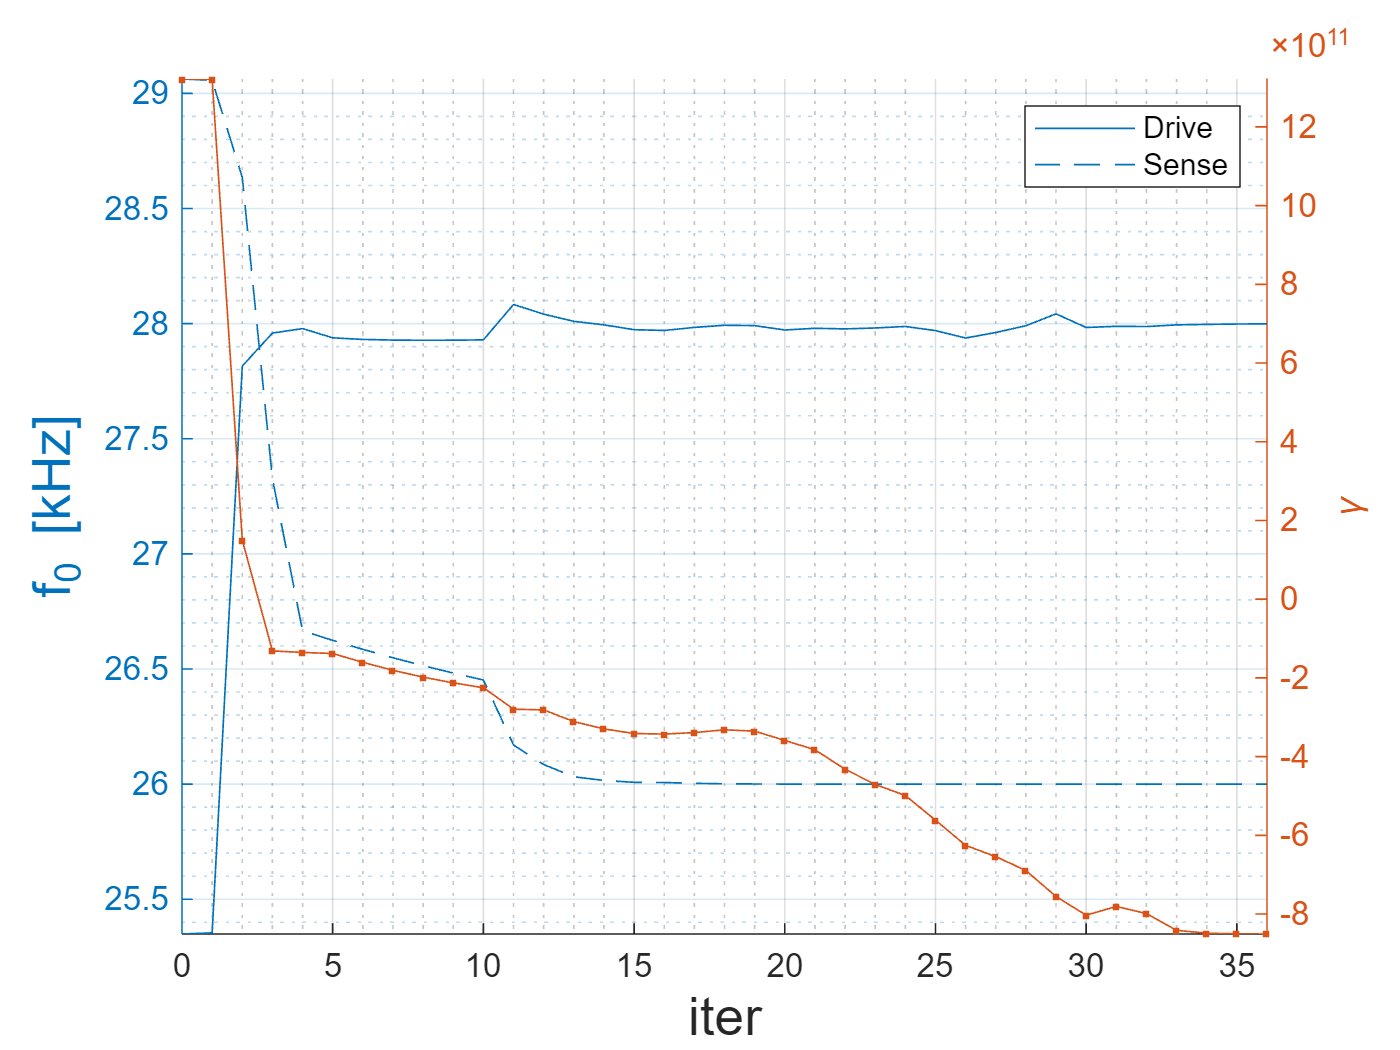

% Initial conditions x = [p]
x0 = p*0;

% Bounds
lb = -[25, 25, 1, 1, 1, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5];
ub =  [25, 25, 1, 1, 1, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5];

args.sys_fun = @(p) build_model(p); % function that evaluates the model at p

args.imod = [1 2];              % mode shape to track
args.f_target = [28 26]*1e3;    % [Hz] mode shape frequency
args.imod_gamma = 1;            % target mode for the nonlinear analysis
args.gamma_target = -1e11;

args.ConstraintTolerance = 1e-10; 

t0=tic;
[xsol,fval,history] = run_fmincon(x0, lb, ub, args);

topt = toc(t0);
fprintf(' Optimization time: %d min %.0f s\n\n', floor(topt/60), rem(topt,60))

 Optimization time: 5 min 35 s



## Optimization results

disp(xsol')

    1.6637
    0.3459
   -0.3848
   -0.2353
   -0.0114
   -0.0754
    1.4692
   -0.2472
    0.7823
   -0.0508
   -0.0754
    1.4691
   -0.2471
    0.7829
   -0.0509



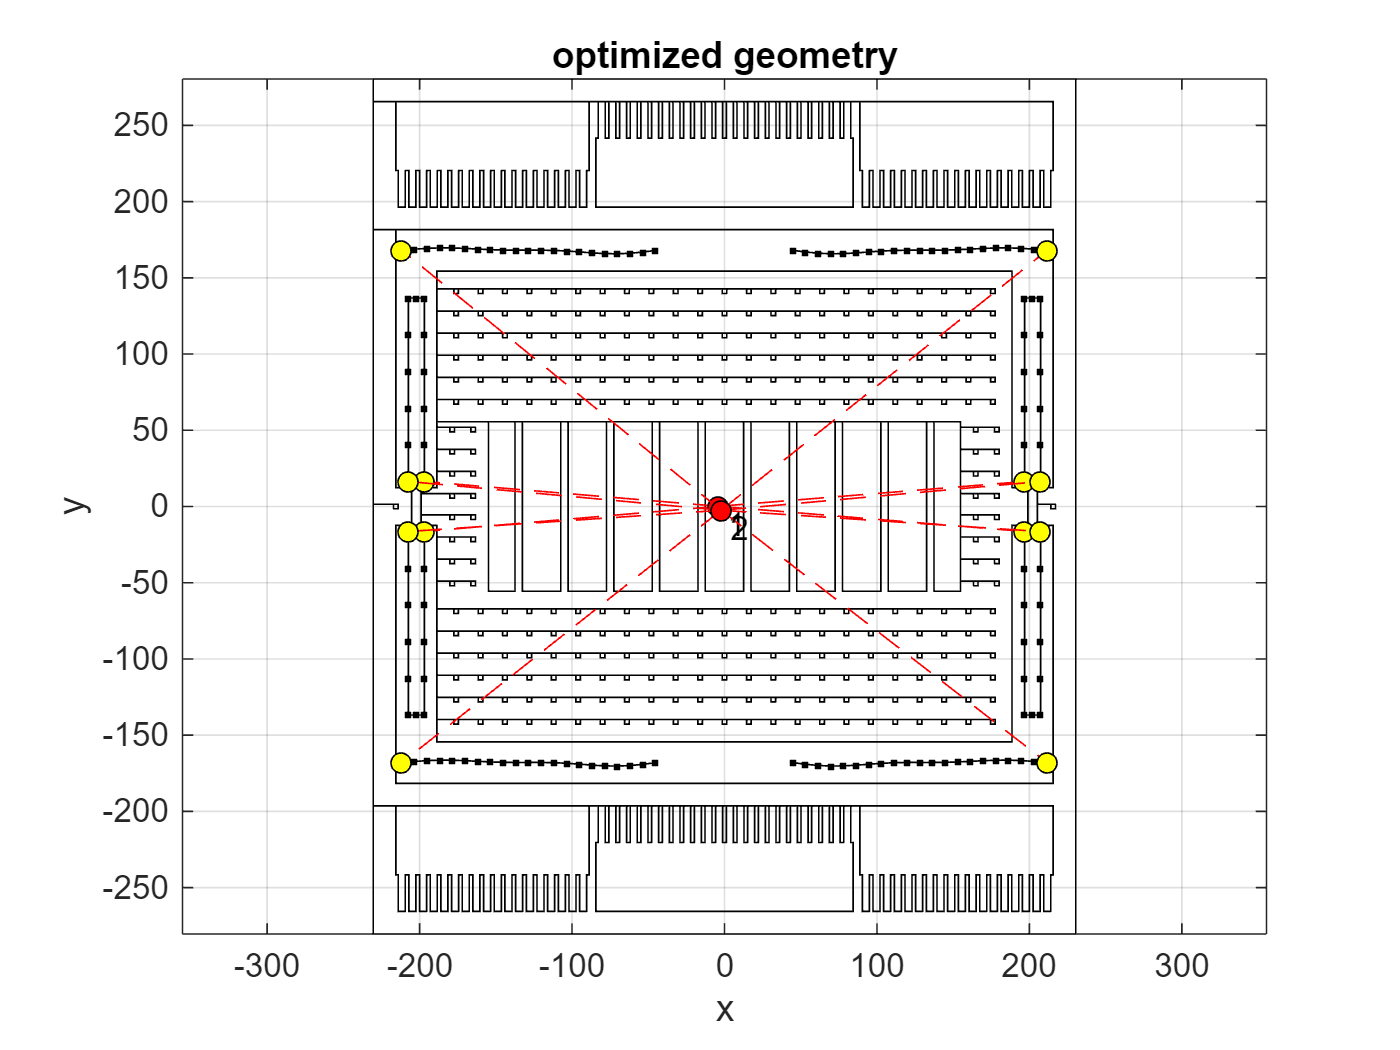

obj = build_model(xsol);
figure
obj.mpc_plot
title('optimized geometry')

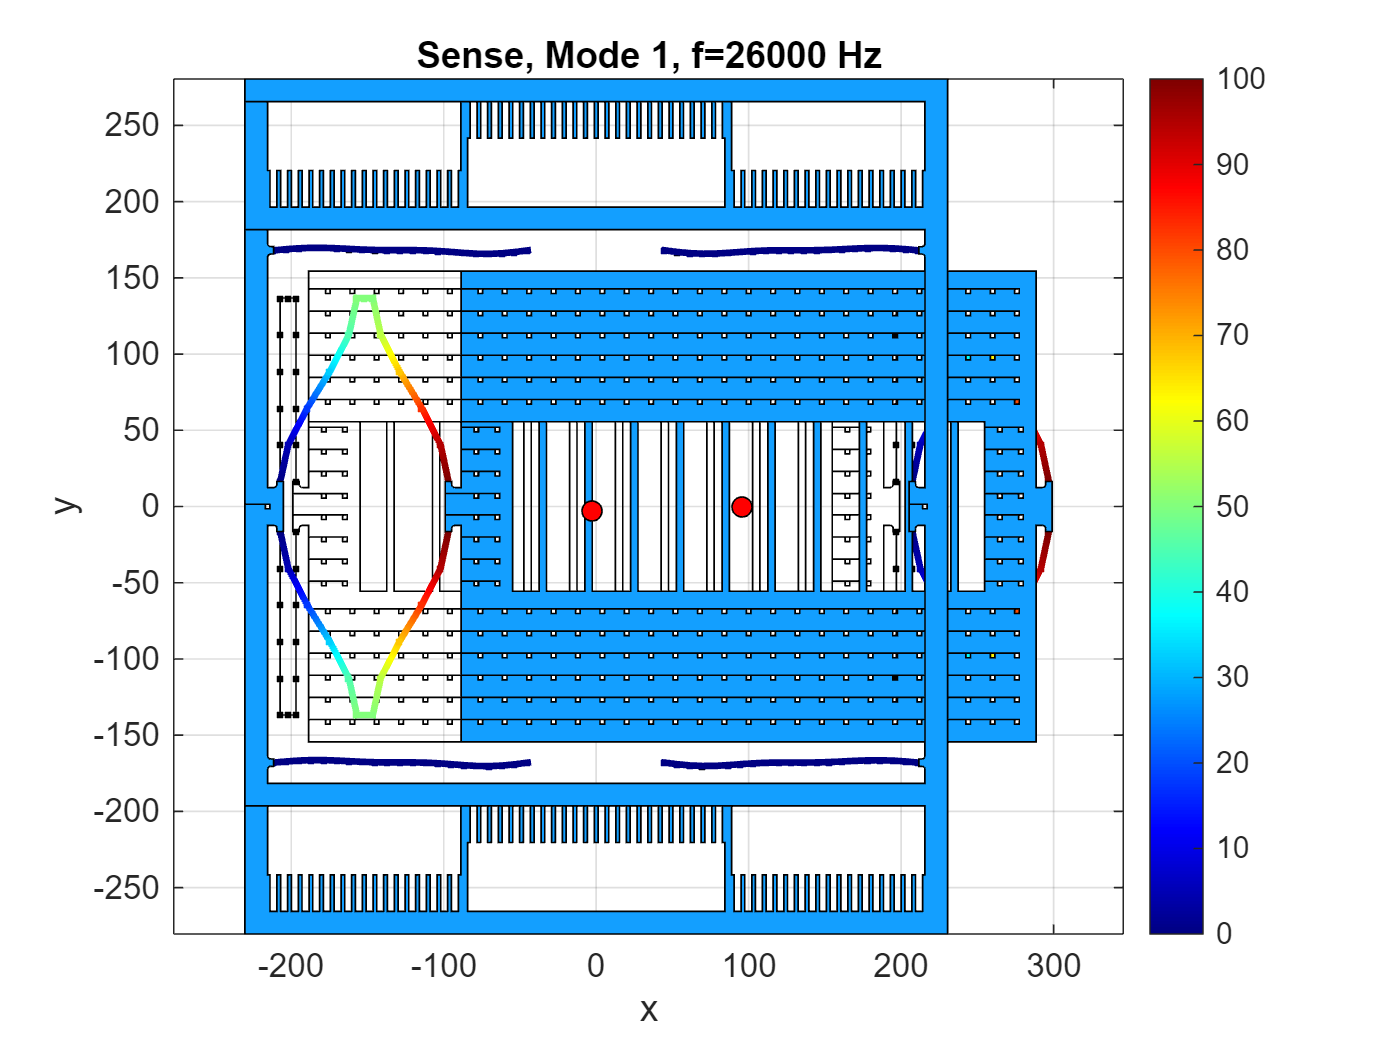

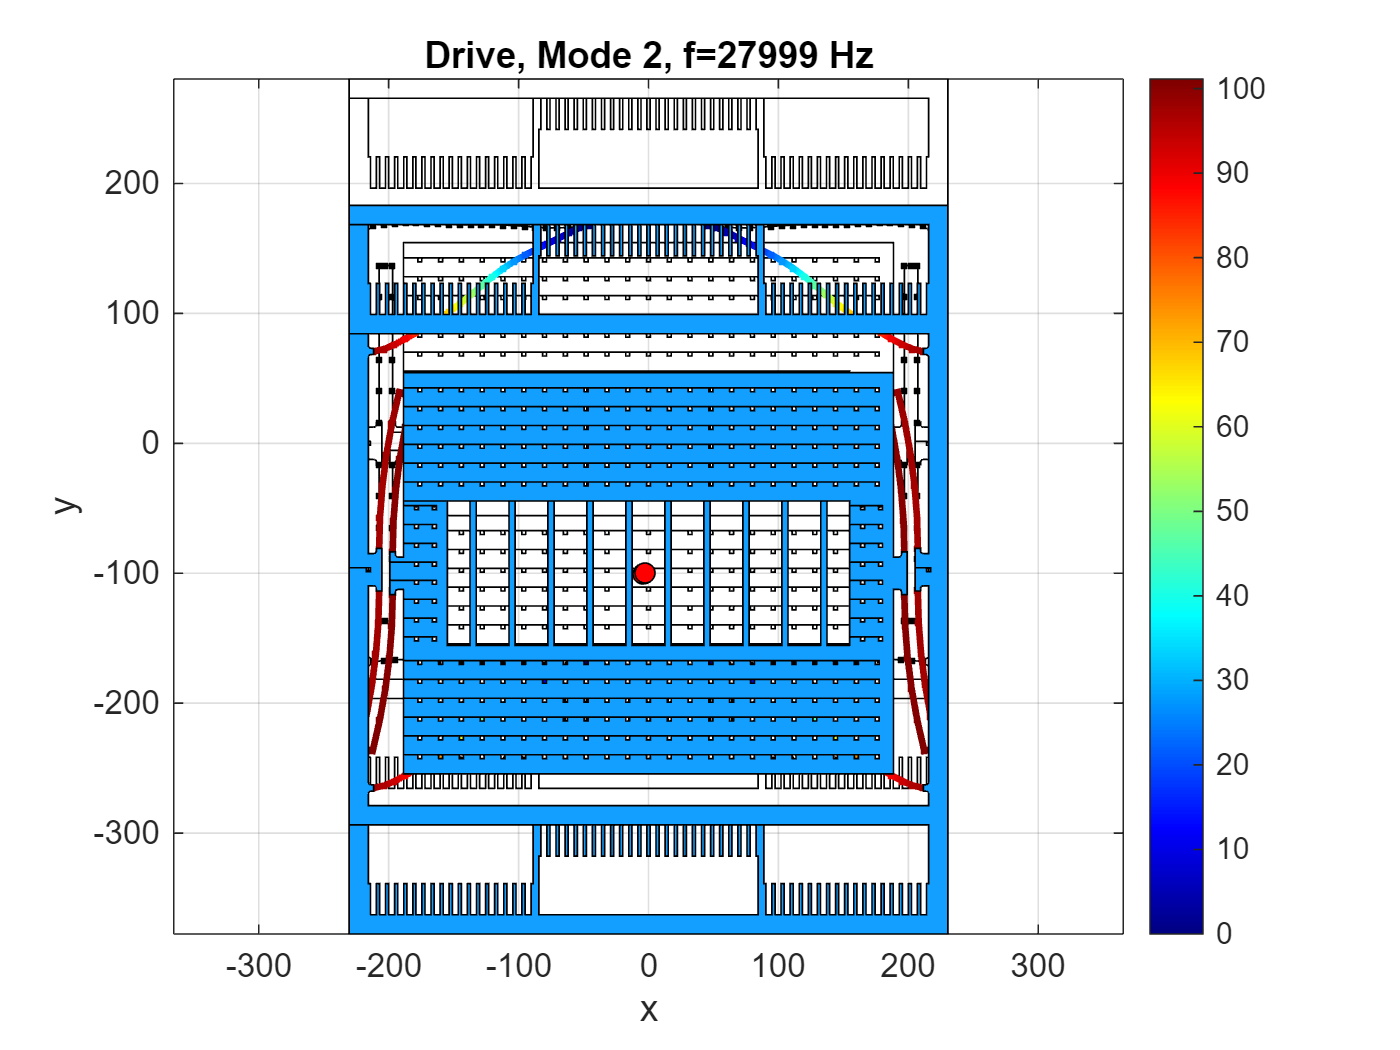

 mode: 2
 dof: 365 
 gamma = -8.5079e+11


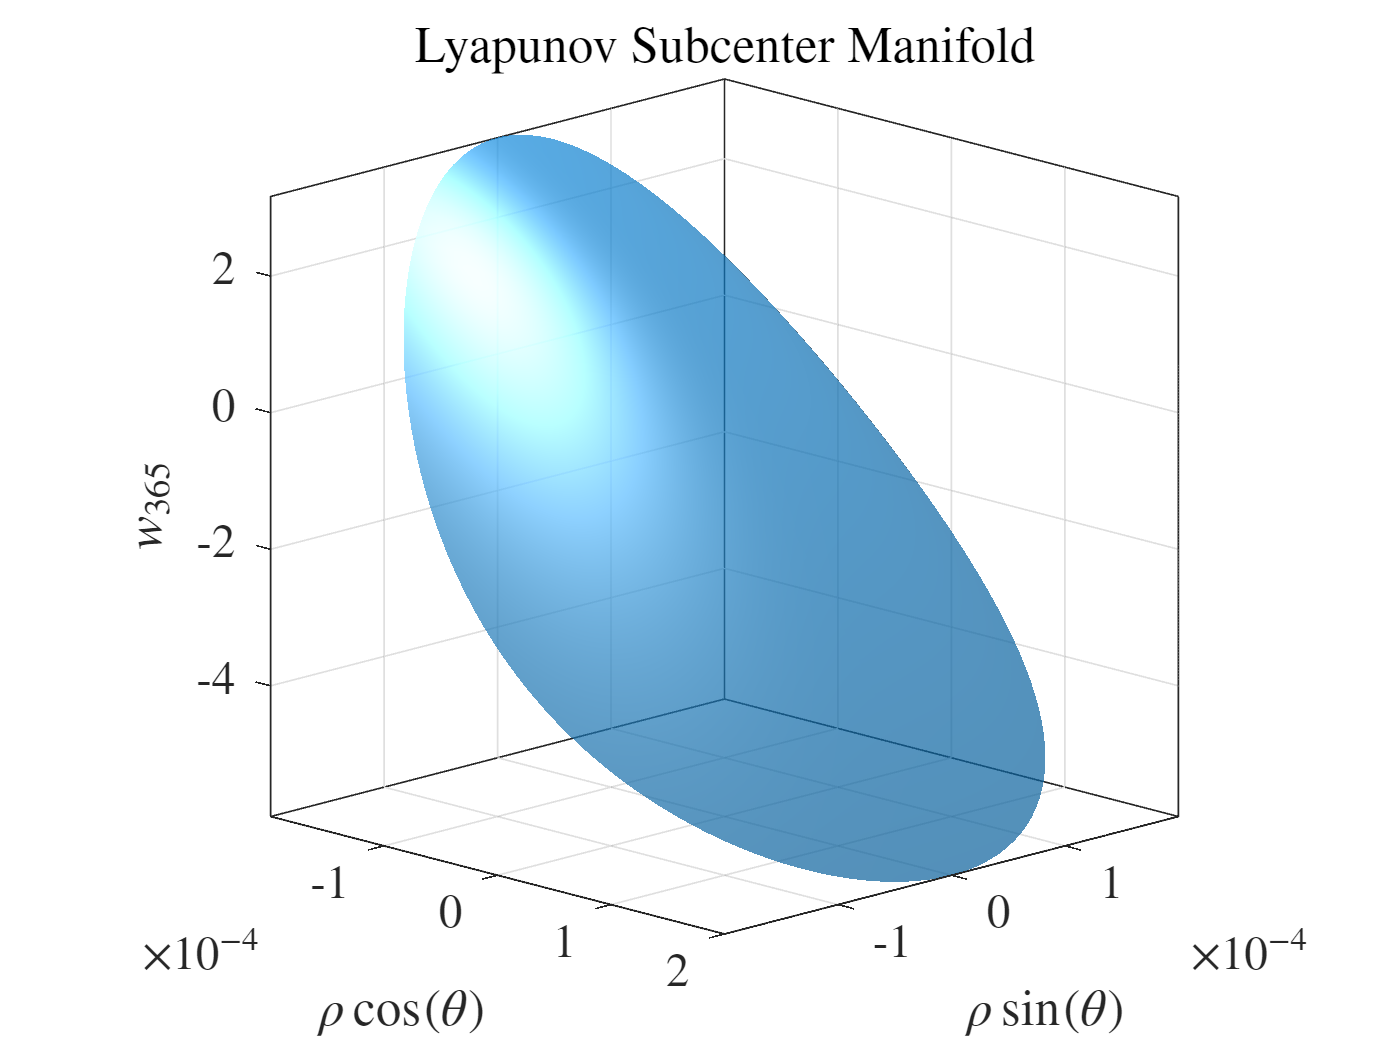

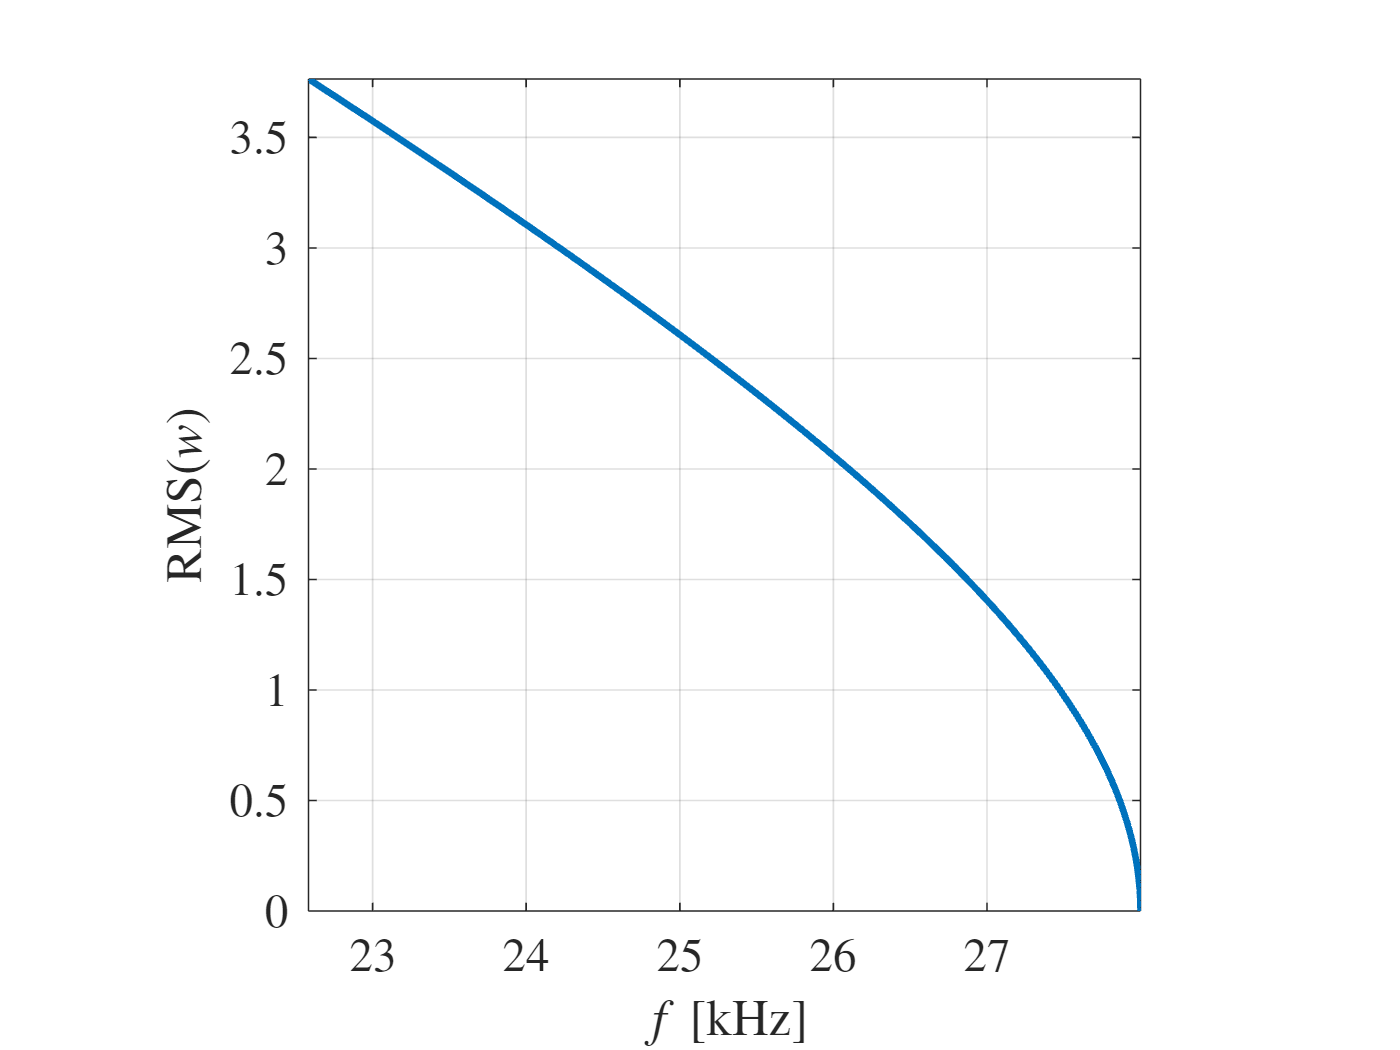

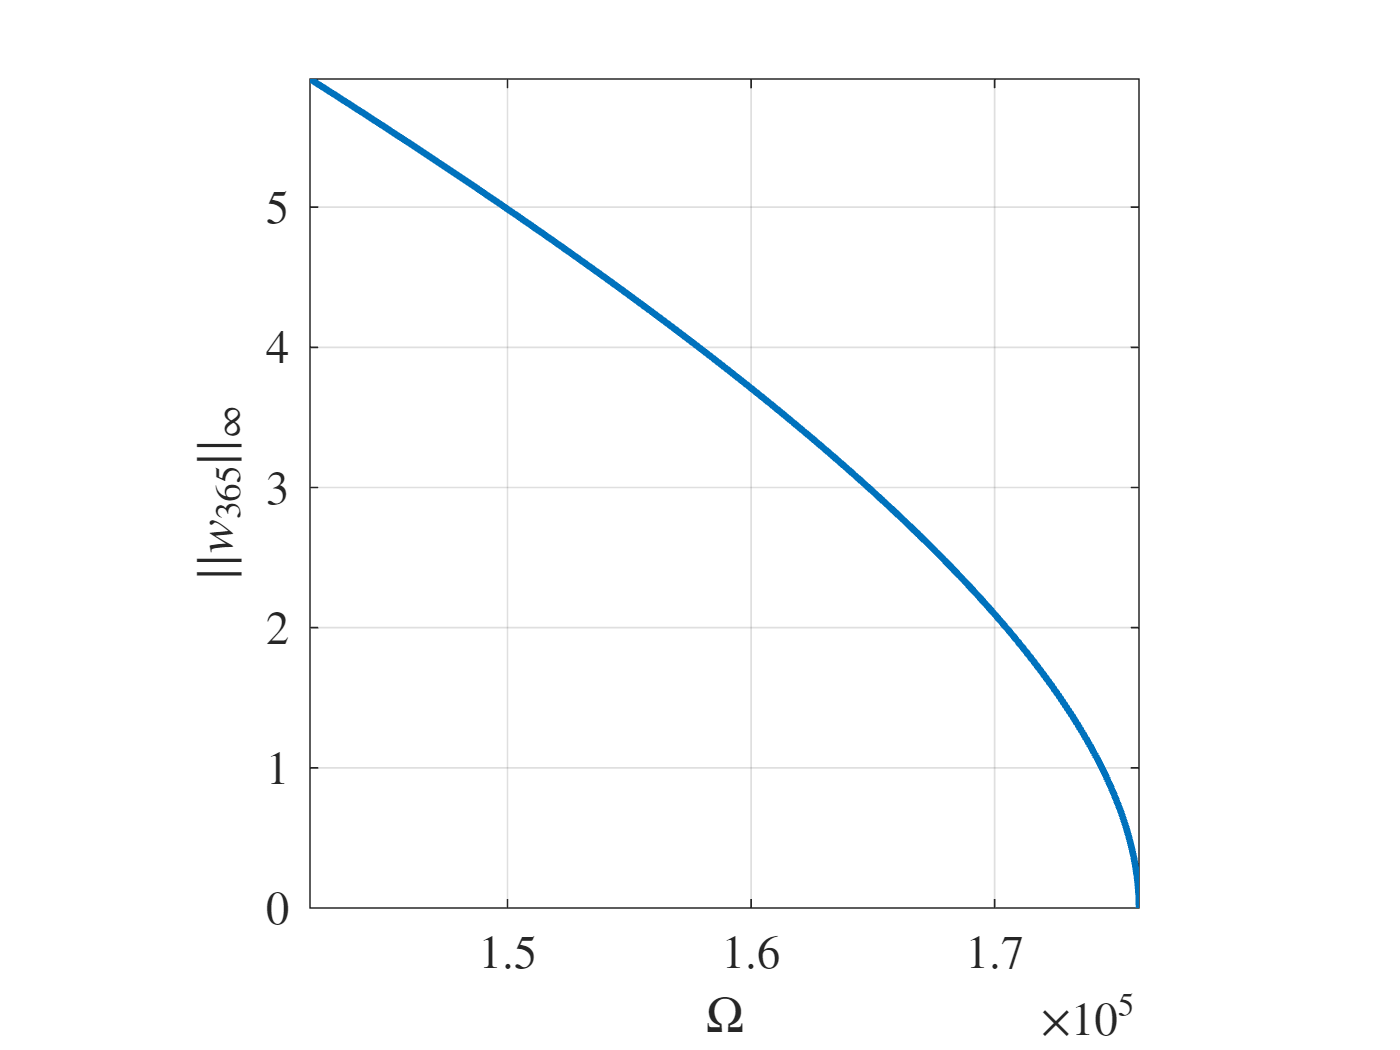

[Omega, wBB_rms, wBB_infNorm] = analyze_system(obj);

## Check accuracy using SSMtool (v2.5-beta)

The backbone curves shown above are computed from a 3rd order LSM expansion, which is valid for low dispacements. To check the accuracy of the result for higher amplitudes, one can use the `SSMtool` expanding at higher orders.

References:

Jain, S., Li, M., Thurnher, T., & Haller, G. (2023). *SSMTool 2.5: Computation of invariant manifolds in high-dimensional mechanics problems* (v2.5-beta). Zenodo. [https://doi.org/10.5281/zenodo.10018285](https://doi.org/10.5281/zenodo.10018285) 

 SSMTool (v2.5 beta) added to path.

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 0
modal damping ratio for 2 mode is 0
modal damping ratio for 3 mode is 0
modal damping ratio for 4 mode is 0
modal damping ratio for 5 mode is 0
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
   1.0e+06 *

   0.0000 + 0.1634i
   0.0000 - 0.1634i
   0.0000 + 0.1759i
   0.0000 - 0.1759i
   0.0000 + 1.0344i
   0.0000 - 1.0344i
   0.0000 + 1.1002i
   0.0000 - 1.1002i
   0.0000 + 2.2144i
   0.0000 - 2.2144i

(near) outer resonance detected for the following combination of master eigenvalues
     1     1
     2     1
     2     2
     3     2
     3     3
     4     3
     4     4
     5     4
     5     5
     1     1
     1     

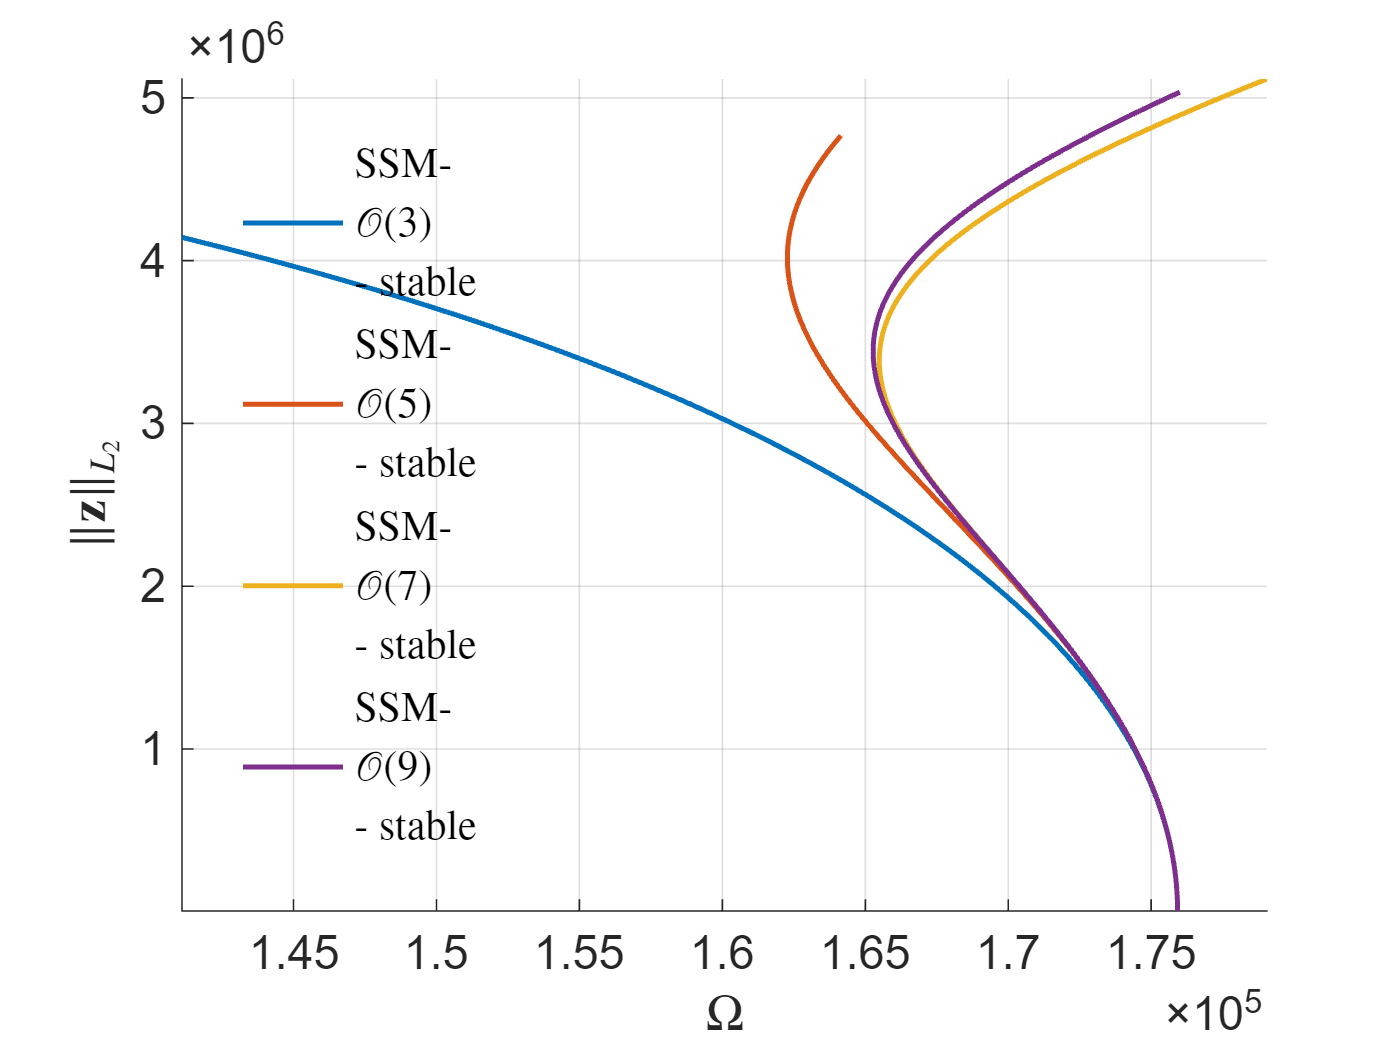

order = [3 5 7 9];
imod = 2;
bb = verify_using_SSMtool(obj, order, imod);

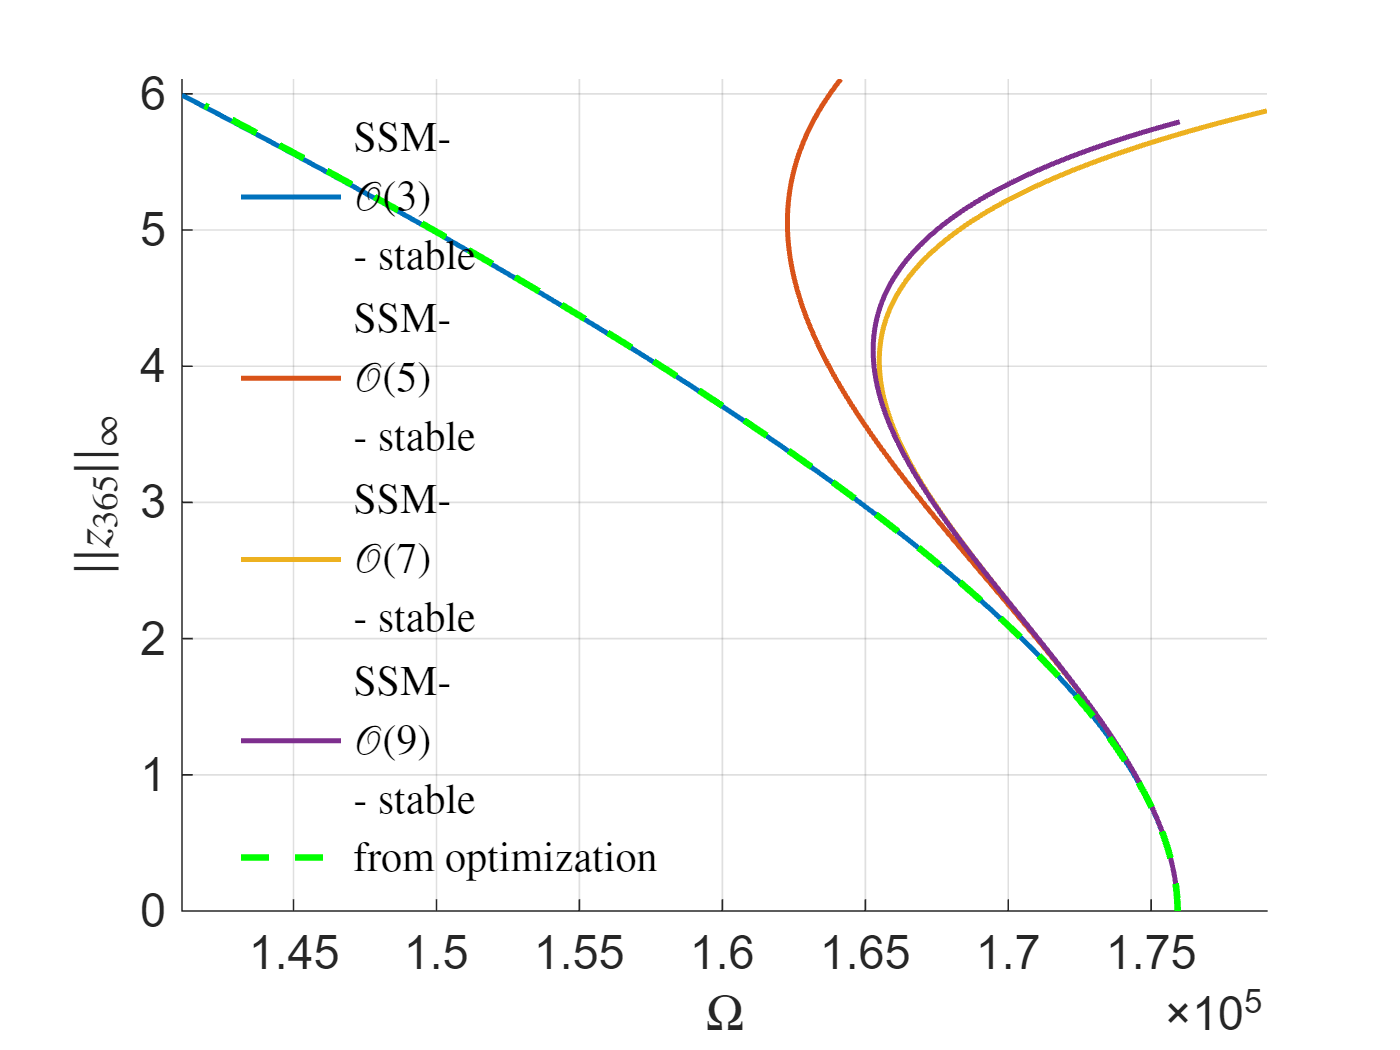

hold on;
plot(Omega, wBB_infNorm, 'g--', 'LineWidth',2,'DisplayName', 'from optimization')

## Frequency Response Curve (FRC) - original geometry

 SSMTool (v2.5 beta) added to path.



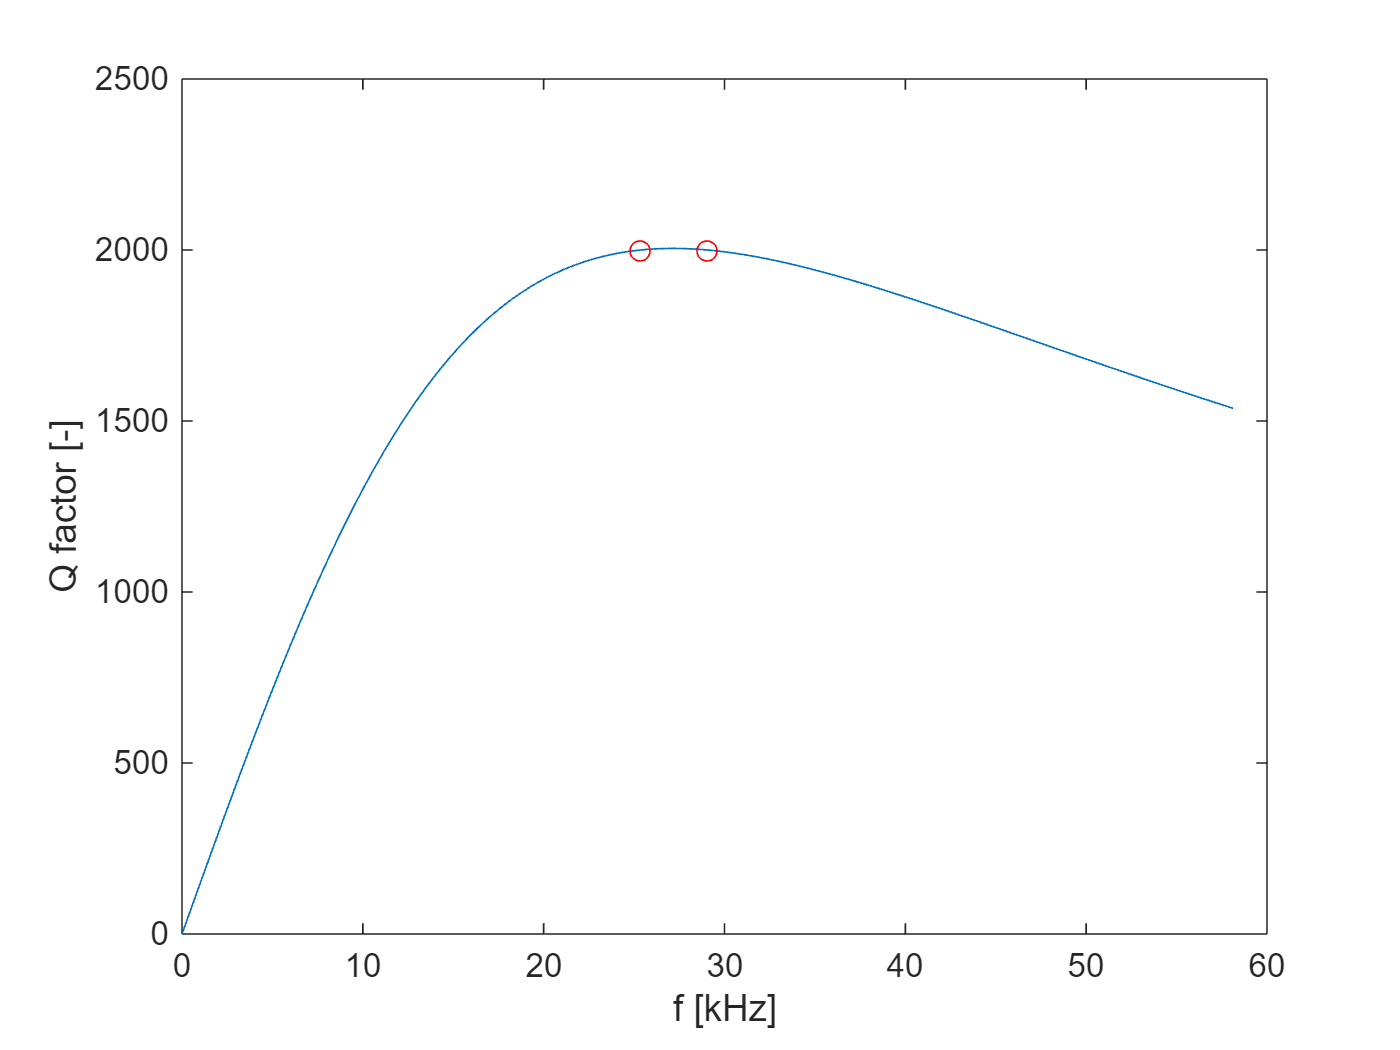

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.500000e-04
modal damping ratio for 2 mode is 2.500000e-04
modal damping ratio for 3 mode is 8.552030e-04
modal damping ratio for 4 mode is 9.024008e-04
modal damping ratio for 5 mode is 1.772064e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
   1.0e+06 *

  -0.0000 + 0.1593i
  -0.0000 - 0.1593i
  -0.0000 + 0.1826i
  -0.0000 - 0.1826i
  -0.0010 + 1.1441i
  -0.0010 - 1.1441i
  -0.0011 + 1.2100i
  -0.0011 - 1.2100i
  -0.0043 + 2.4113i
  -0.0043 - 2.4113i

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 107
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
    

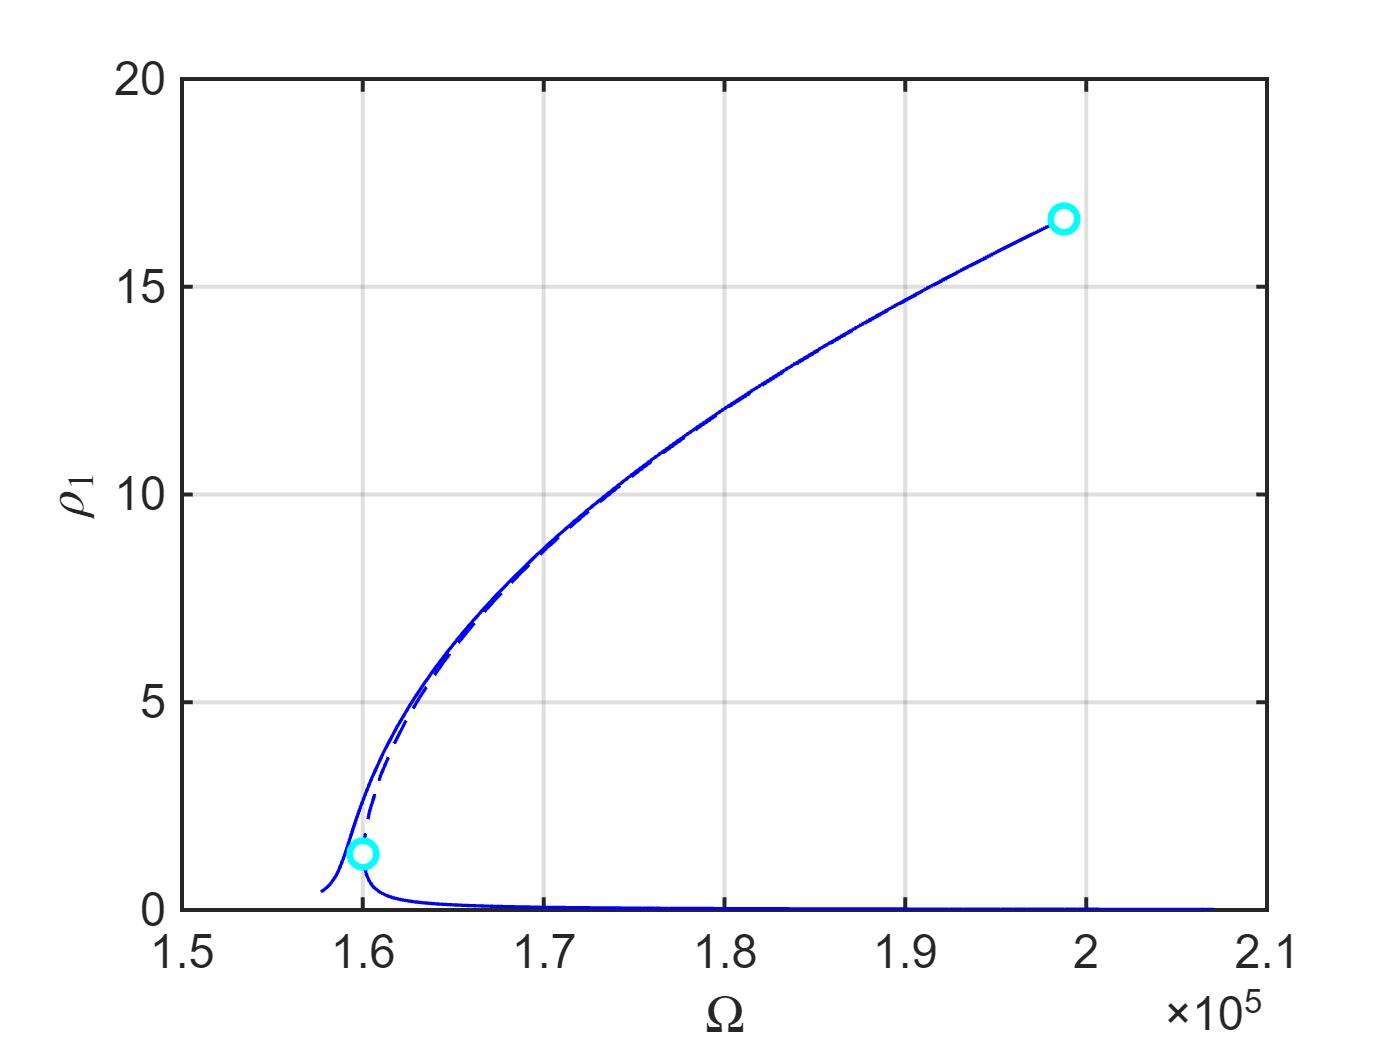

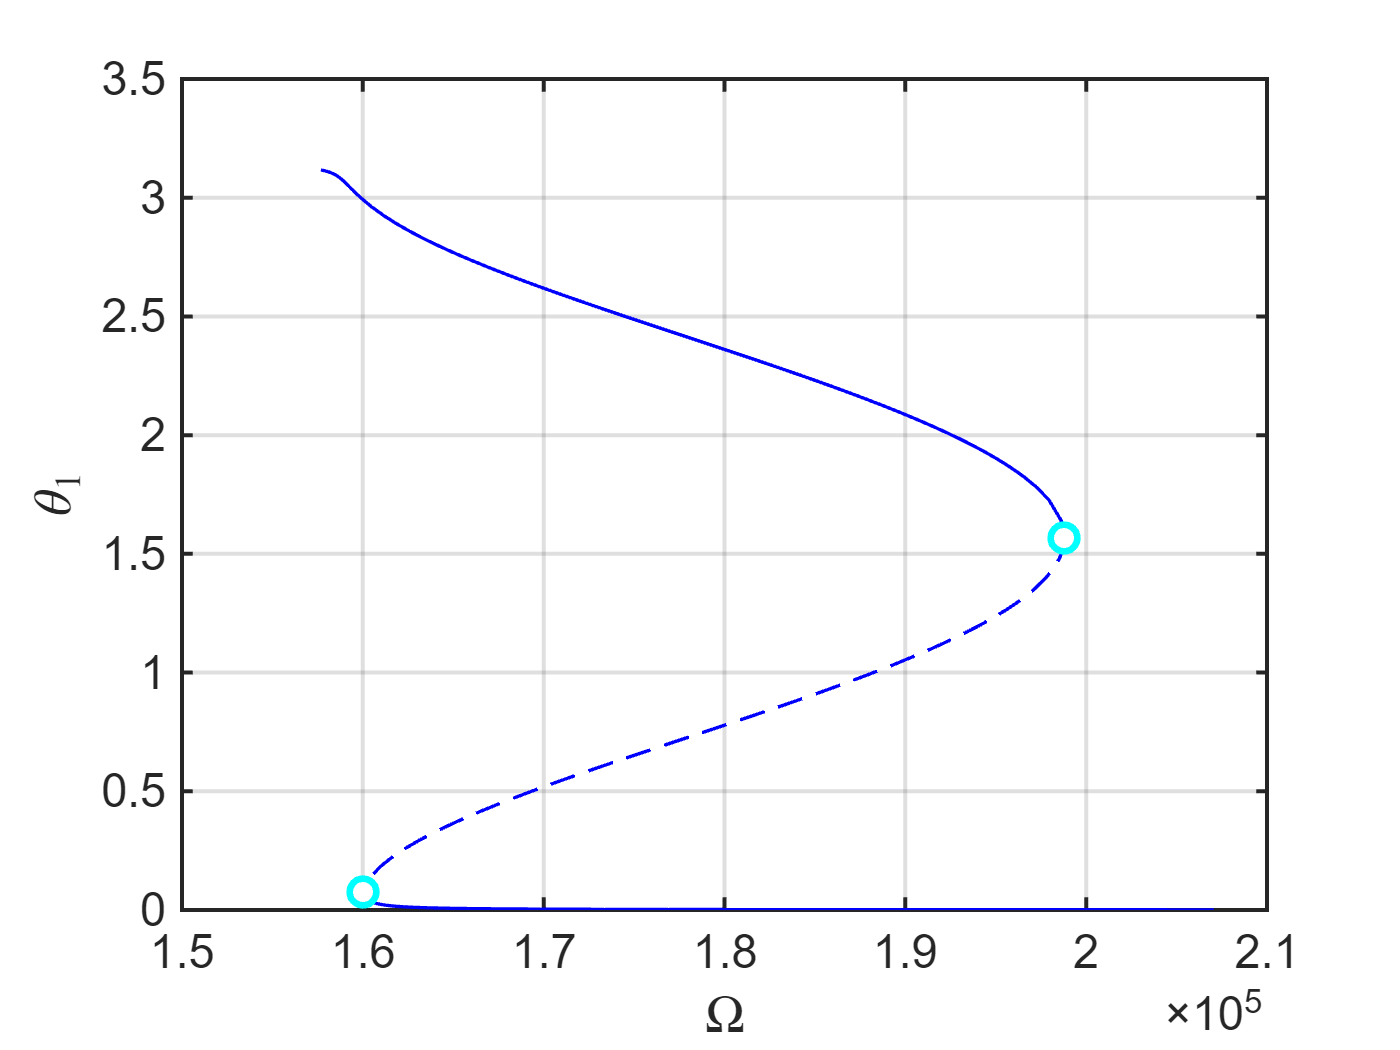

the forcing frequency 1.5768e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5786e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5810e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5832e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5853e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5864e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5894e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5910e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5918e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5922e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequenc

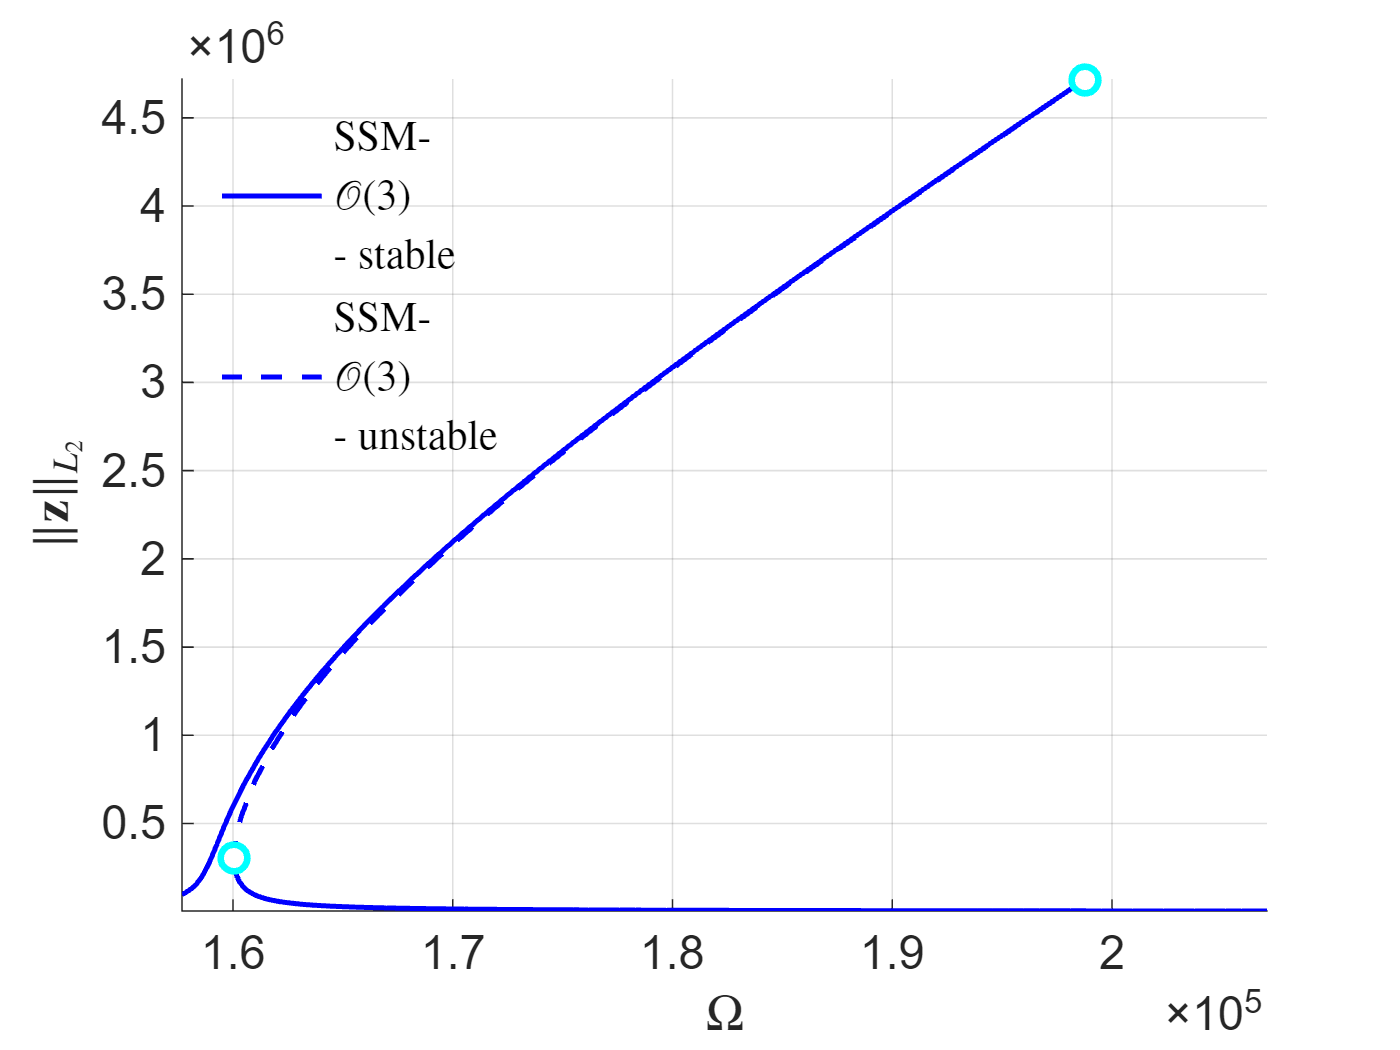

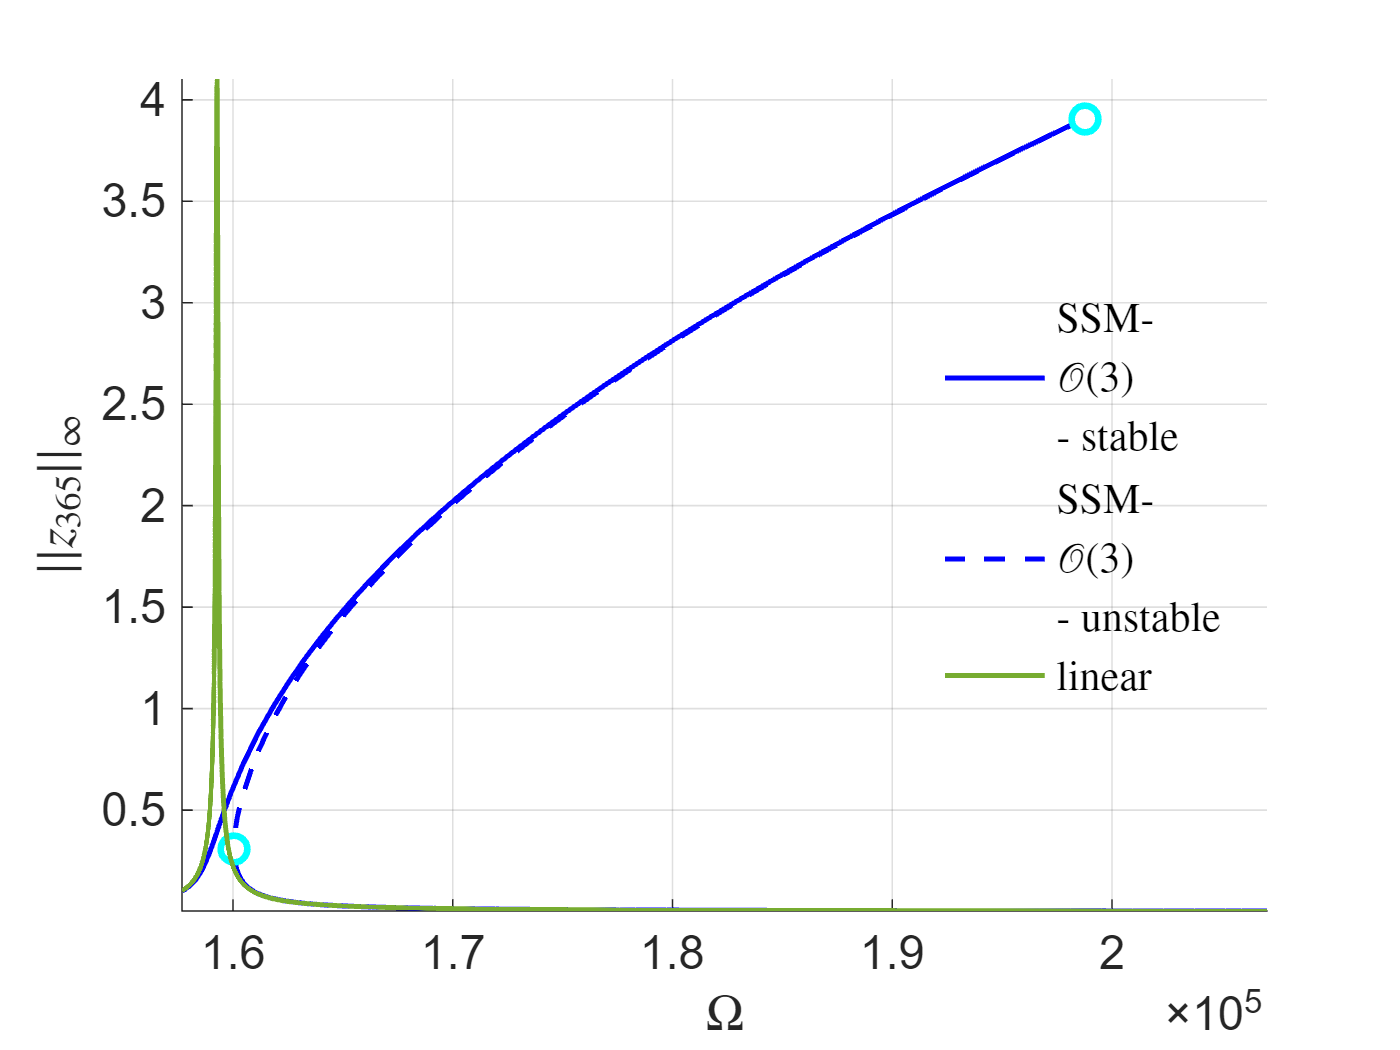

Elapsed time is 23.774736 seconds.


obj = build_model(xsol*0);
imod = 1; % drive mode
order = 3;
Qfactor = [2000 2000];
epsilon = 0.42; % [uN]
omegaRange_norm = [0.99 1.3]; % normalized over the selected eigenfrequency
FRC_p0 = FRC_using_SSMtool(obj,order,imod,Qfactor,epsilon,omegaRange_norm);

## Frequency Response Curve (FRC) - optimized geometry, SSM-O(3)

 SSMTool (v2.5 beta) added to path.



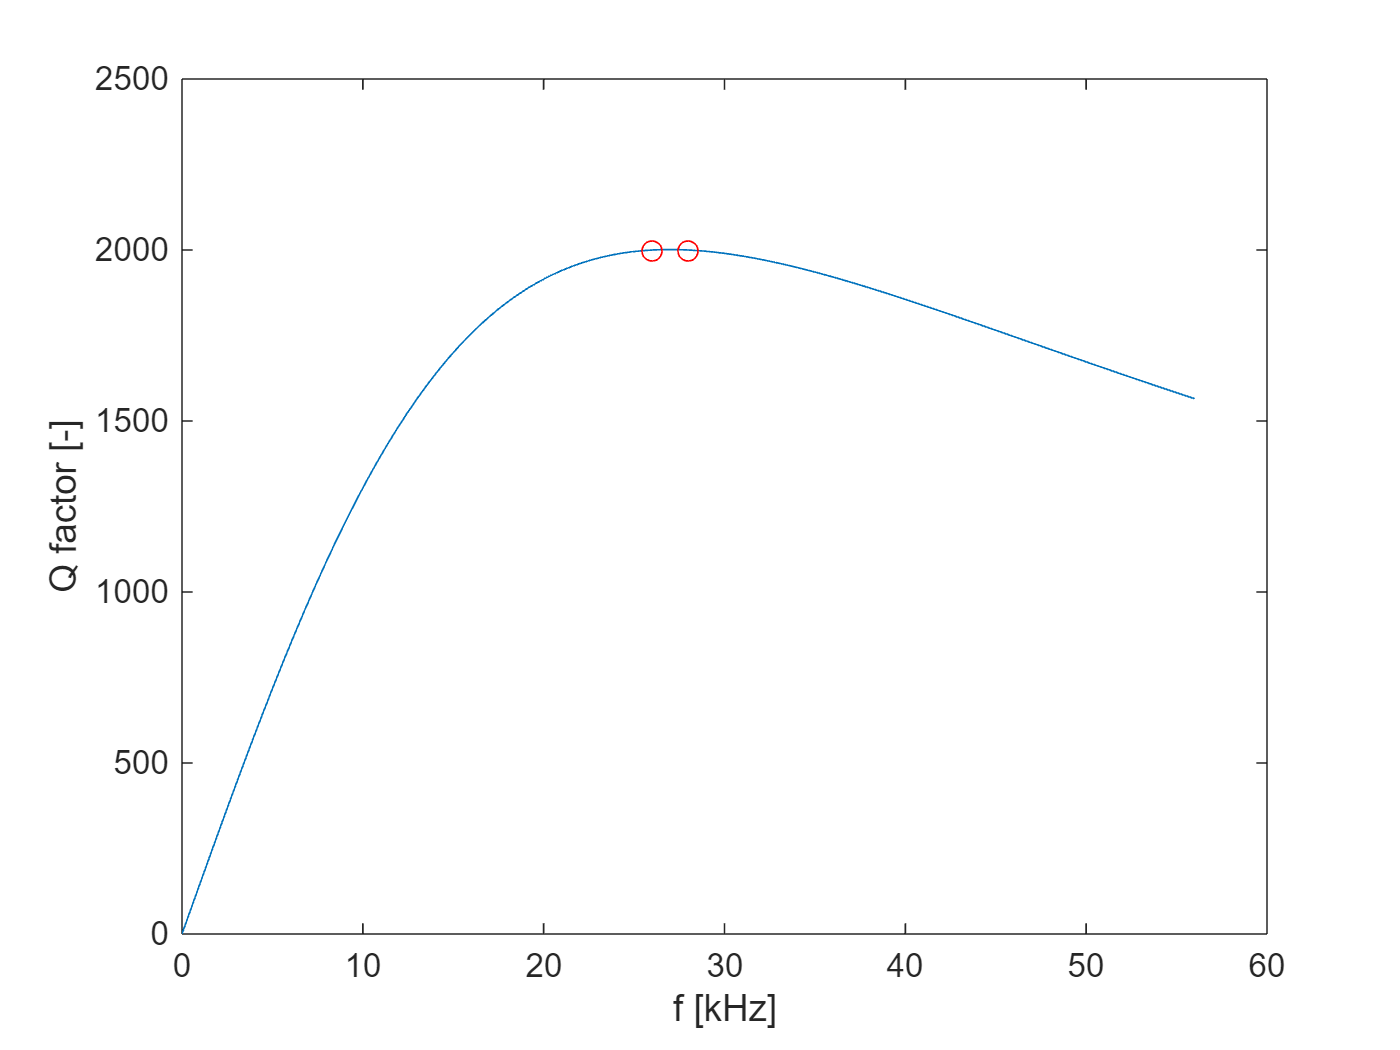

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.500000e-04
modal damping ratio for 2 mode is 2.500000e-04
modal damping ratio for 3 mode is 7.826844e-04
modal damping ratio for 4 mode is 8.299538e-04
modal damping ratio for 5 mode is 1.641221e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
   1.0e+06 *

  -0.0000 + 0.1634i
  -0.0000 - 0.1634i
  -0.0000 + 0.1759i
  -0.0000 - 0.1759i
  -0.0008 + 1.0344i
  -0.0008 - 1.0344i
  -0.0009 + 1.1002i
  -0.0009 - 1.1002i
  -0.0036 + 2.2144i
  -0.0036 - 2.2144i

(near) outer resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in reson

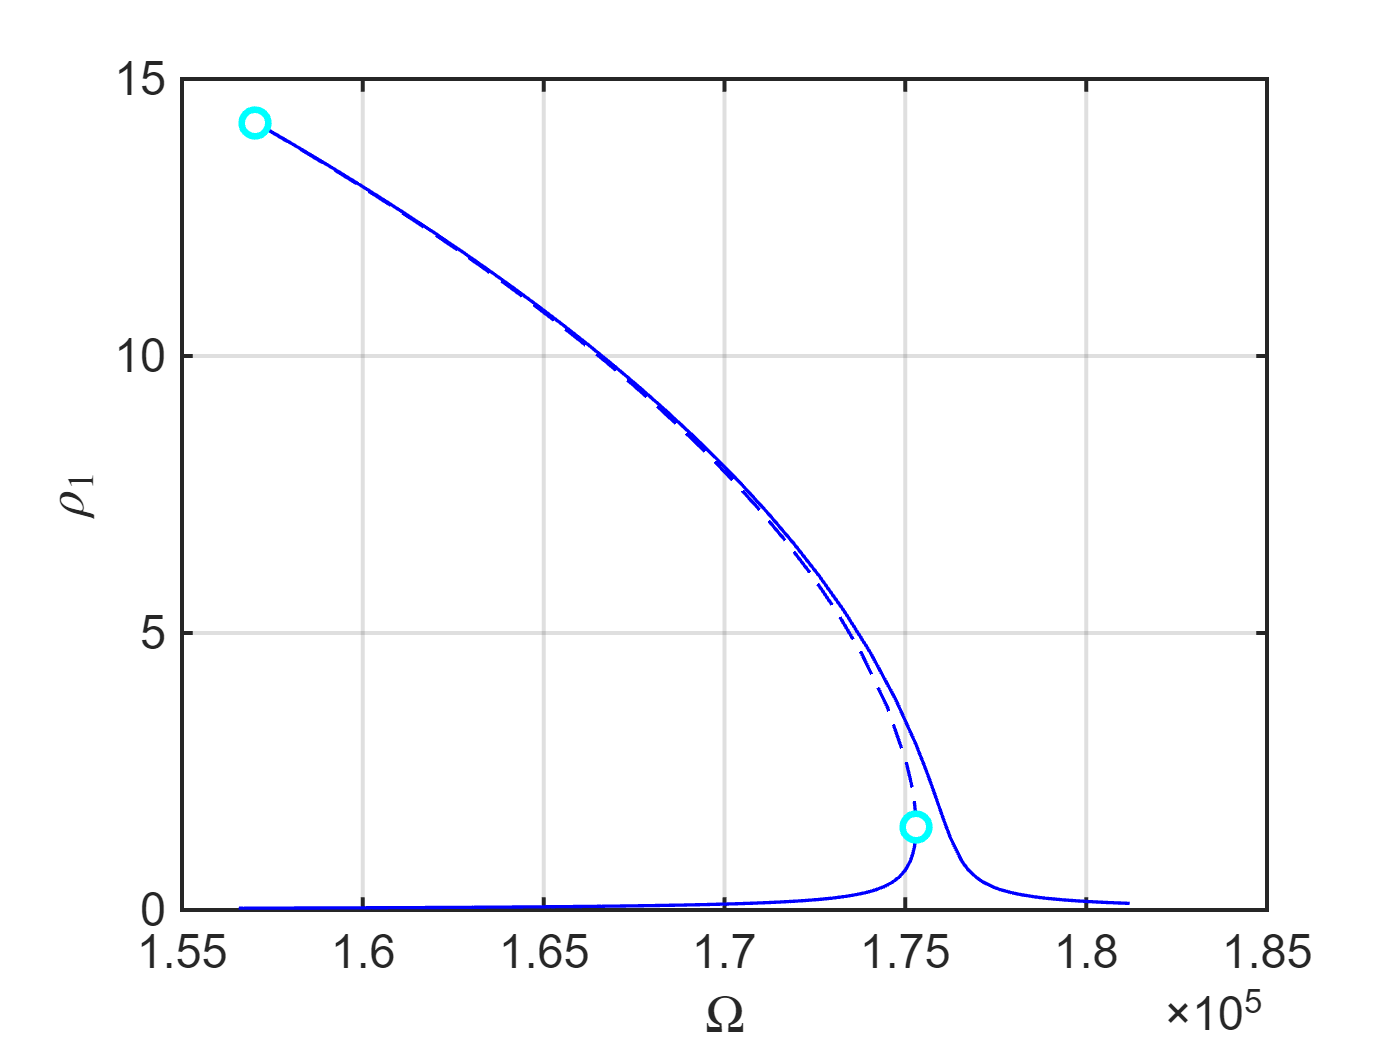

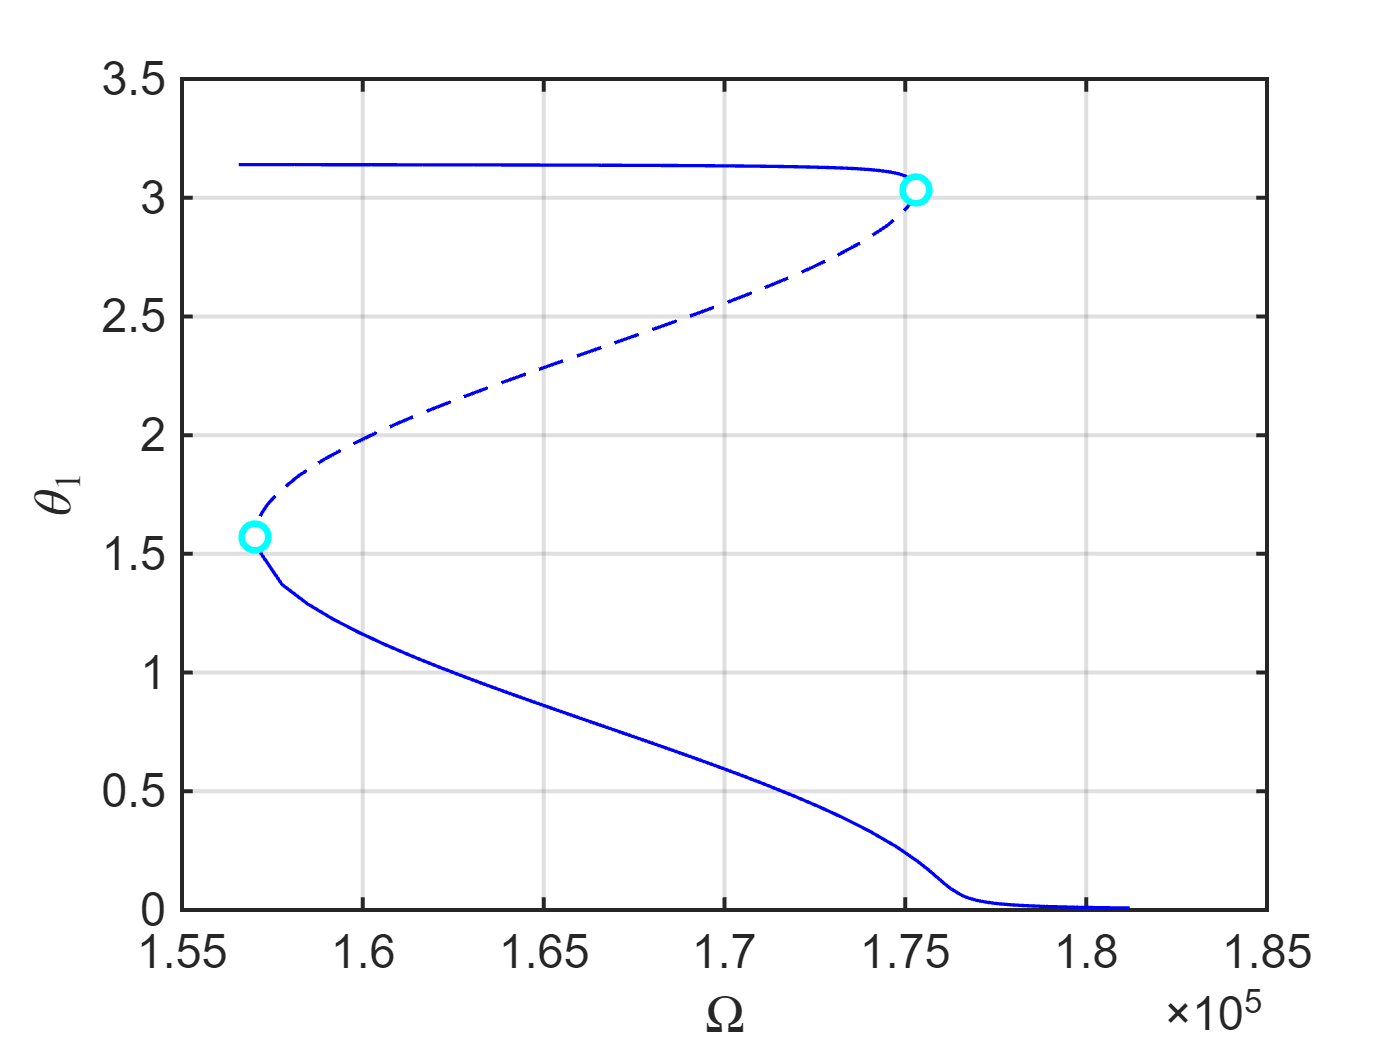

the forcing frequency 1.5657e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.5670e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.5741e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.5811e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.5882e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.5953e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6023e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6094e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6165e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6236e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequenc

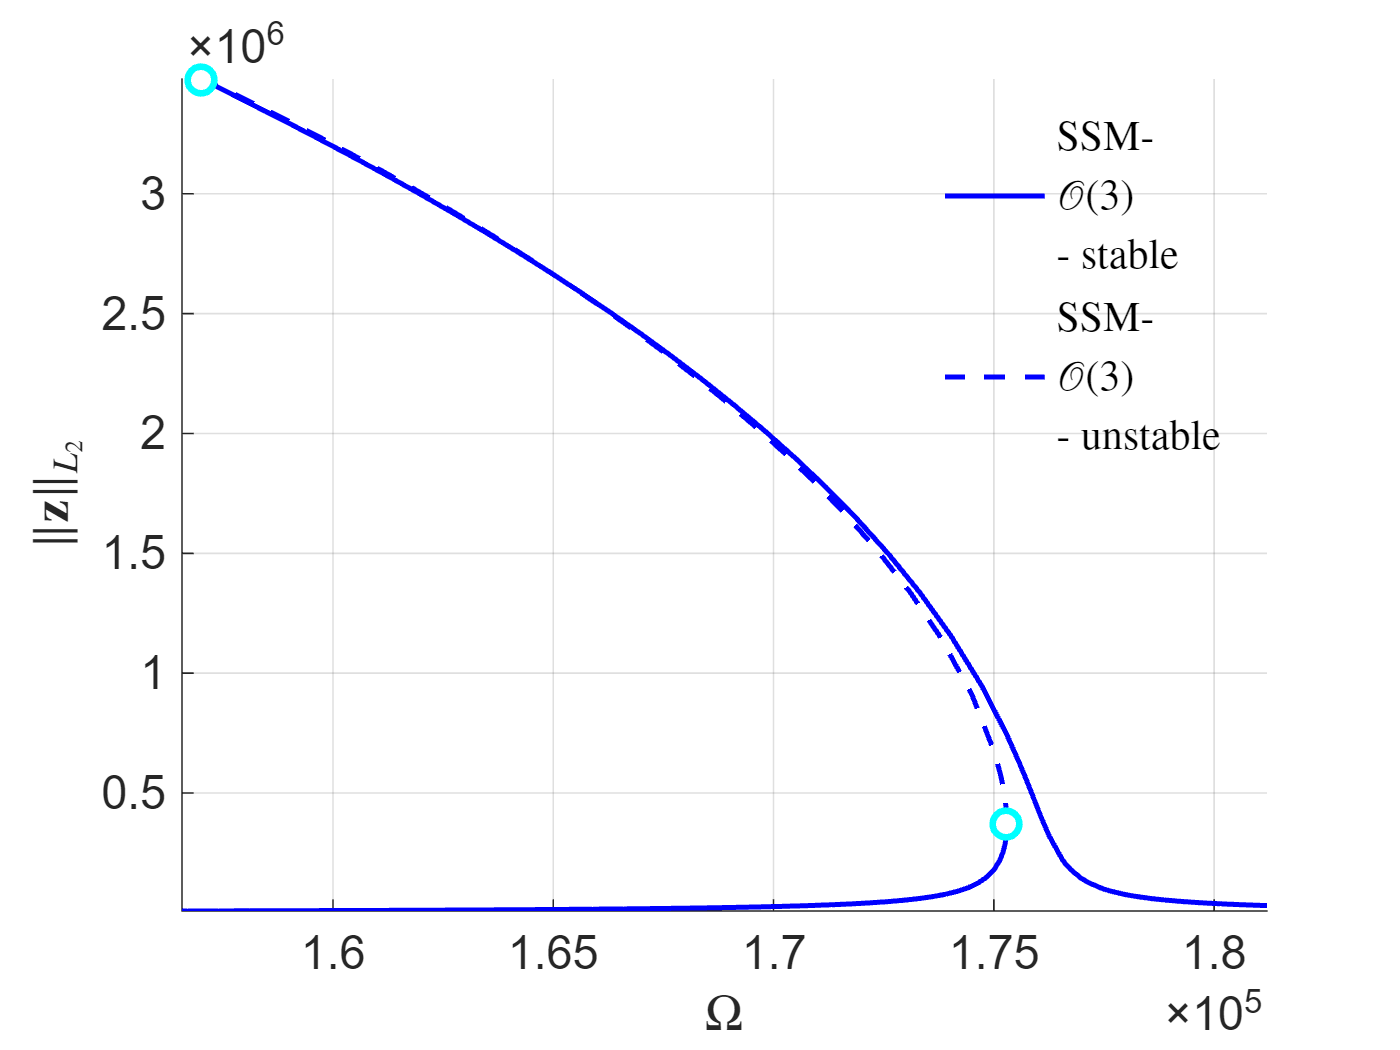

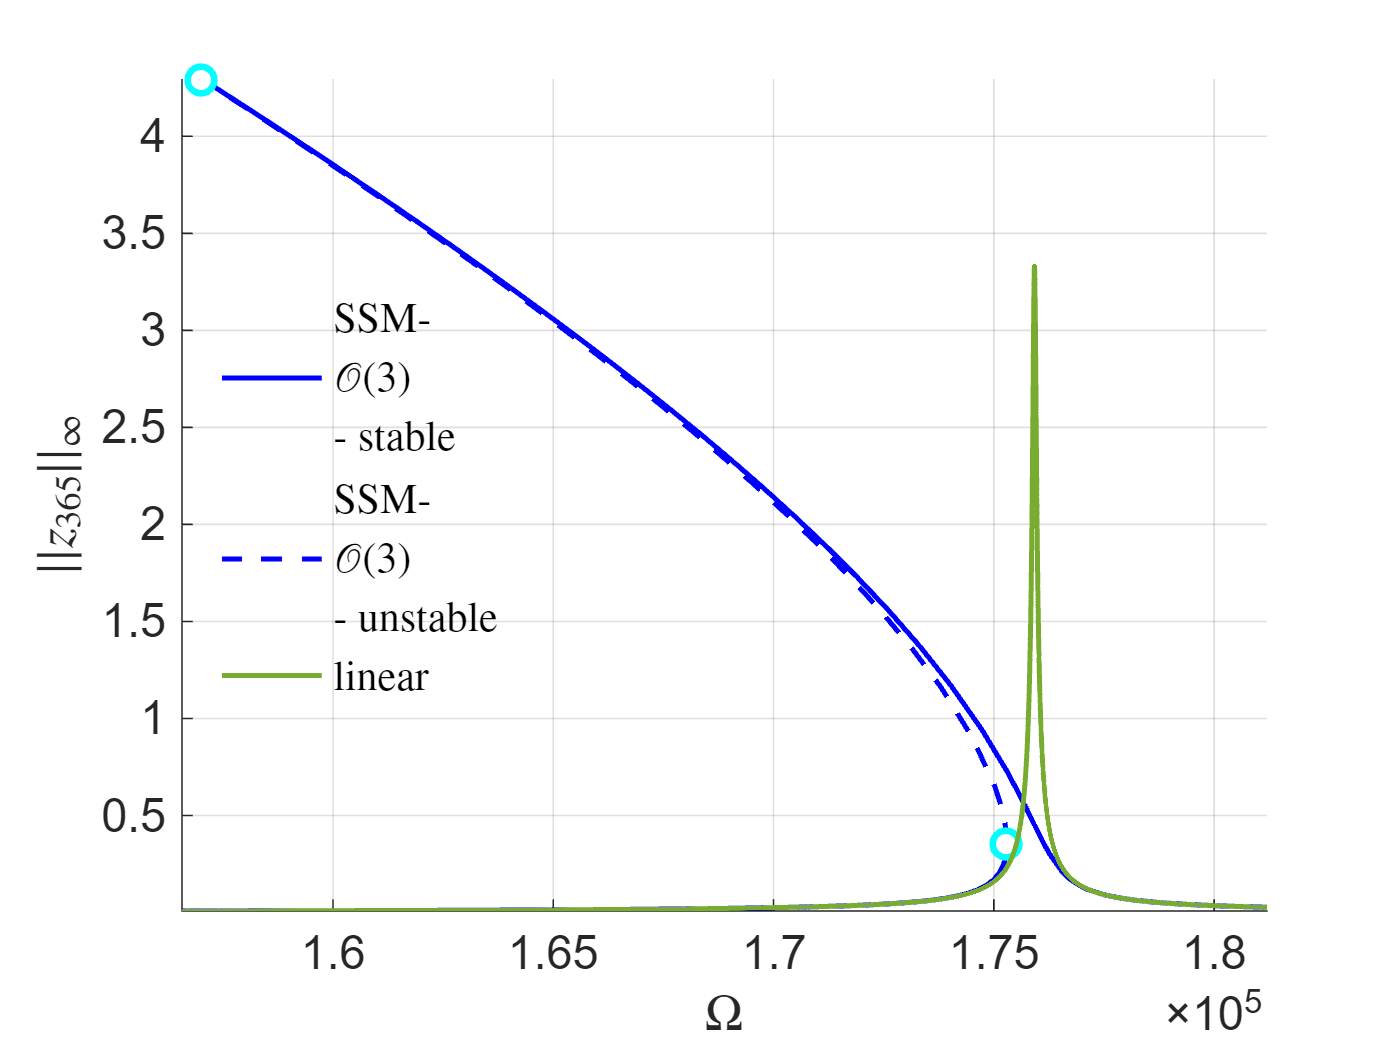

Elapsed time is 18.081025 seconds.


obj = build_model(xsol);
order = 3;
imod = 2; % drive mode
Qfactor = [2000 2000];
epsilon = 0.42; % [uN]
omegaRange_norm = [0.89 1.03]; % normalized over the selected eigenfrequency
FRC_p3 = FRC_using_SSMtool(obj,order,imod,Qfactor,epsilon,omegaRange_norm);

## Frequency Response Curve (FRC) - optimized geometry, SSM-O(9)

 SSMTool (v2.5 beta) added to path.



Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.500000e-04
modal damping ratio for 2 mode is 2.500000e-04
modal damping ratio for 3 mode is 7.826844e-04
modal damping ratio for 4 mode is 8.299538e-04
modal damping ratio for 5 mode is 1.641221e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
   1.0e+06 *

  -0.0000 + 0.1634i
  -0.0000 - 0.1634i
  -0.0000 + 0.1759i
  -0.0000 - 0.1759i
  -0.0008 + 1.0344i
  -0.0008 - 1.0344i
  -0.0009 + 1.1002i
  -0.0009 - 1.1002i
  -0.0036 + 2.2144i
  -0.0036 - 2.2144i

(near) outer resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in reson

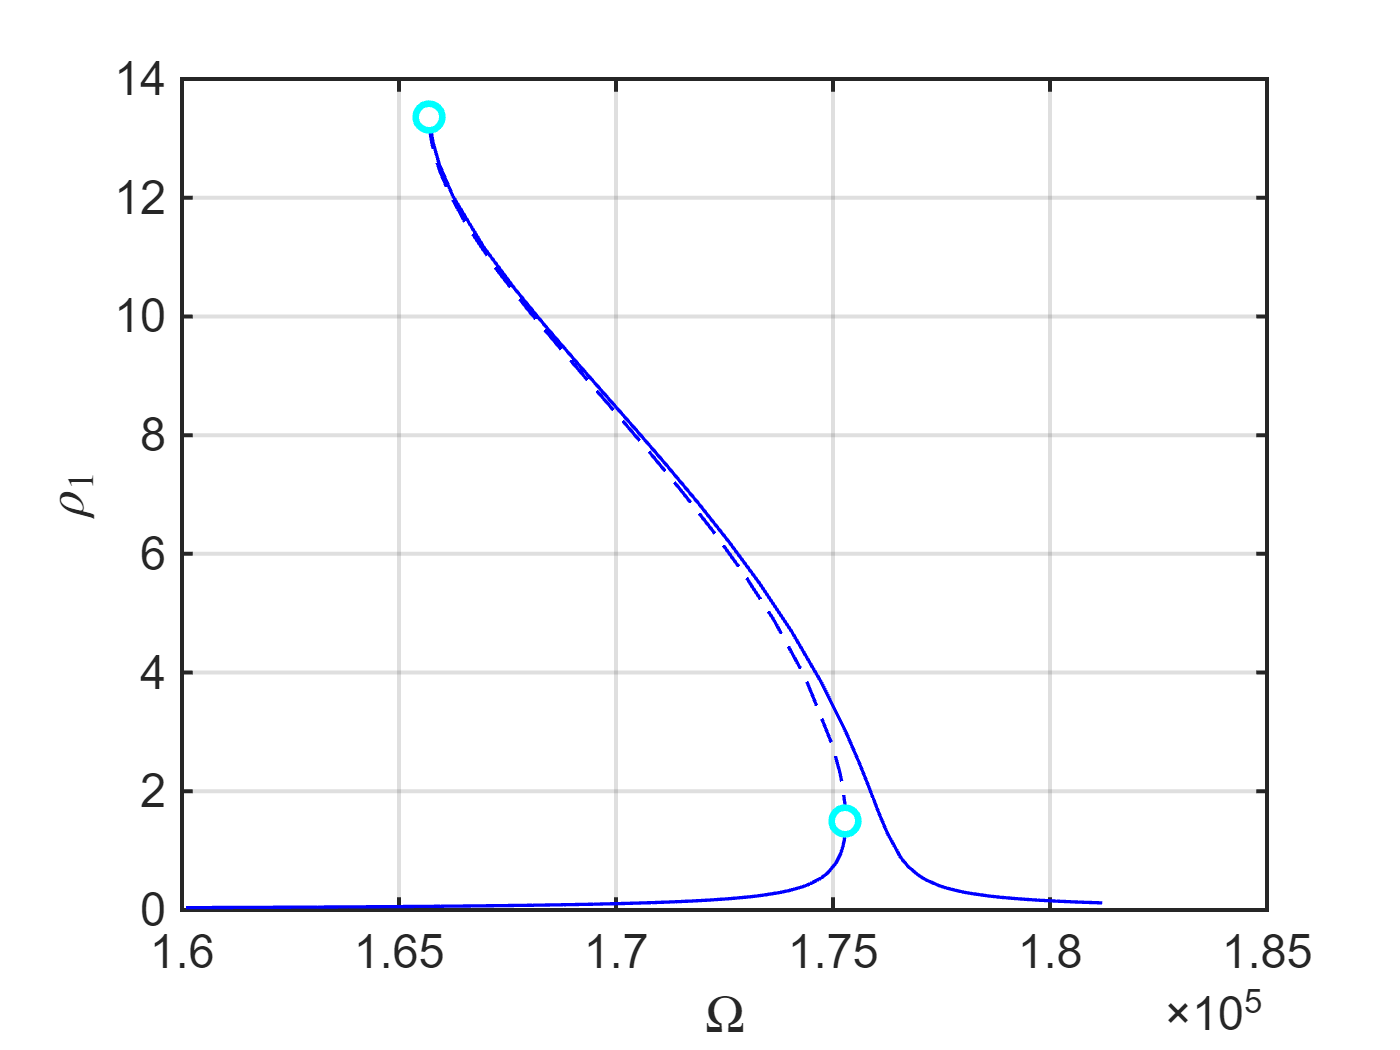

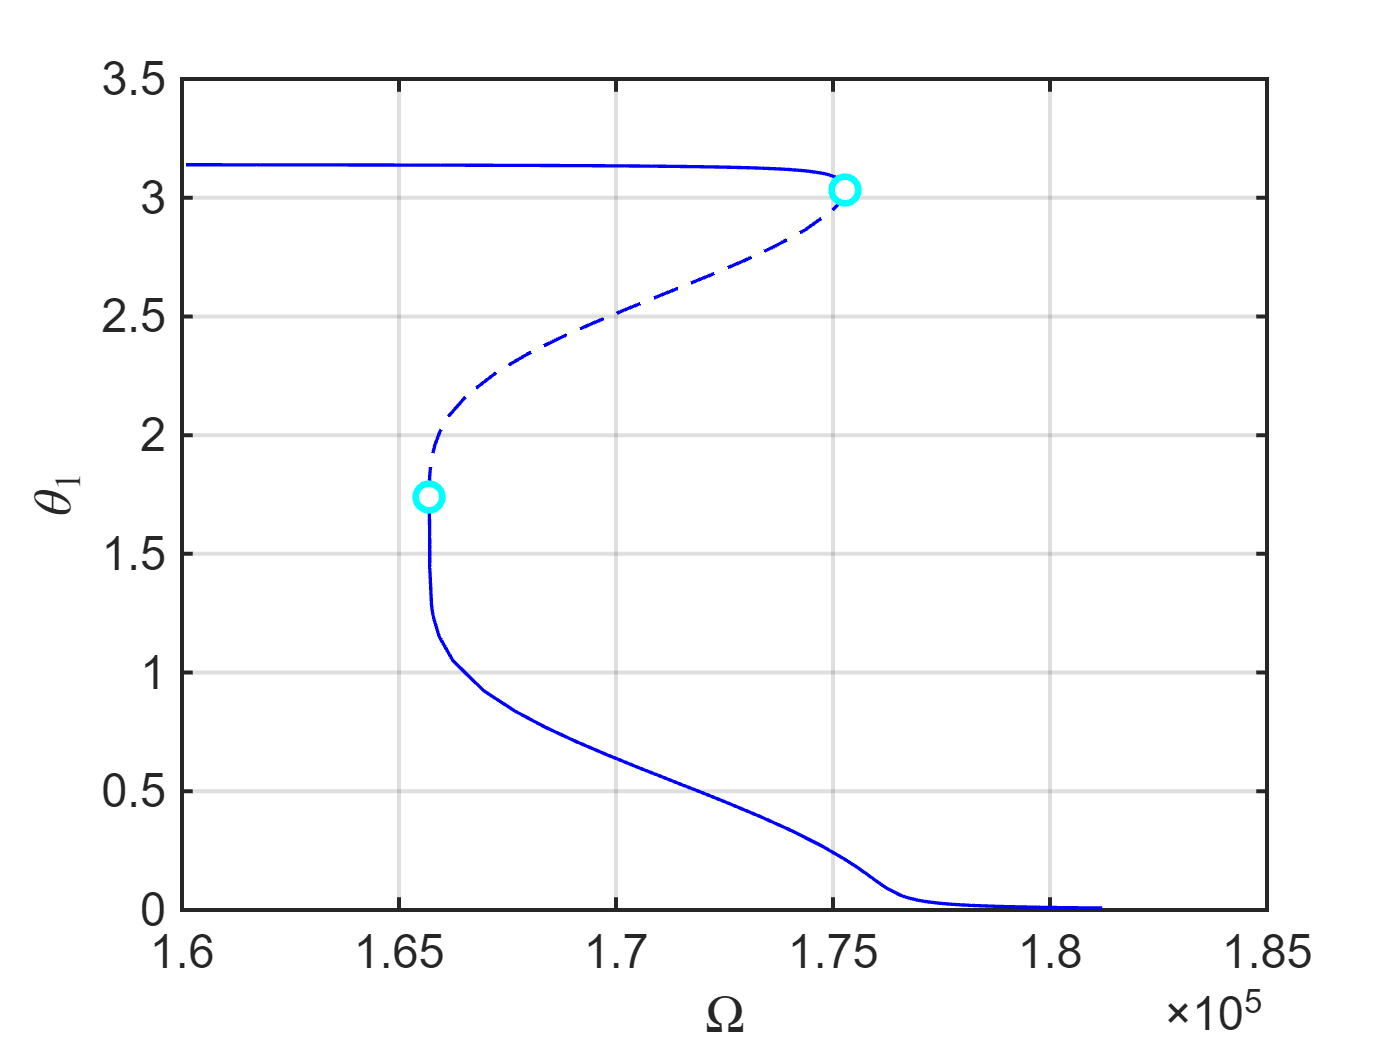

the forcing frequency 1.6009e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6030e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6101e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6171e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6242e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6313e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6383e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6454e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6525e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequency 1.6596e+05 is nearly resonant with the eigenvalue -4.3981e+01 + i1.7592e+05
the forcing frequenc

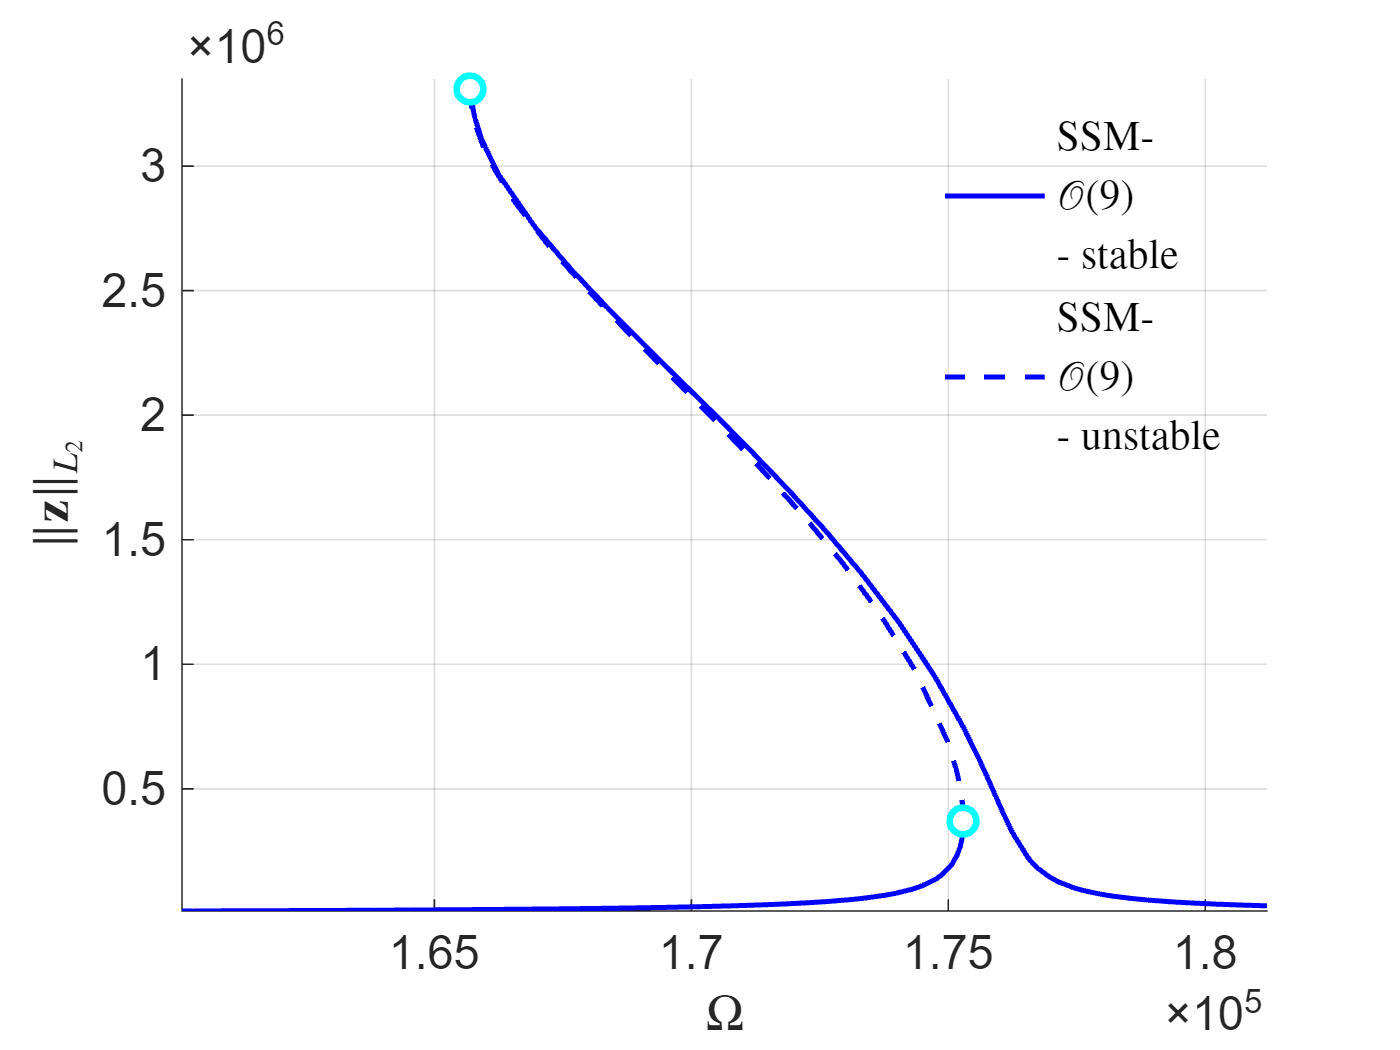

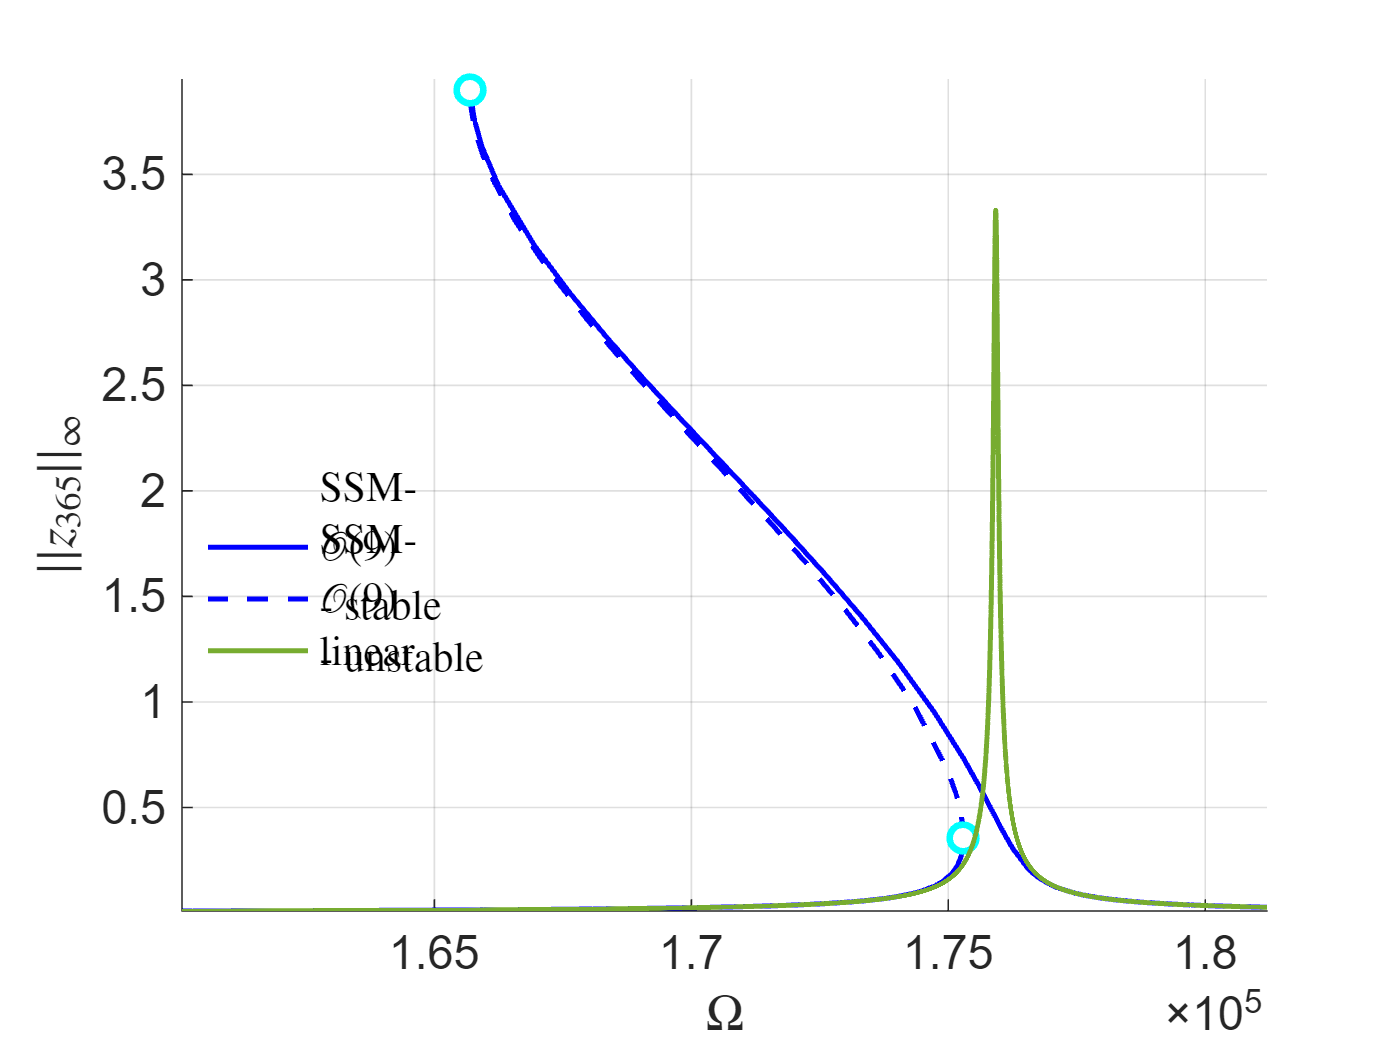

Elapsed time is 21.321458 seconds.


obj = build_model(xsol);
order = 9;
imod = 2; % drive mode
Qfactor = [2000 2000];
epsilon = 0.42; % [uN]
omegaRange_norm = [0.91 1.03]; % normalized over the selected eigenfrequency
FRC_p9 = FRC_using_SSMtool(obj,order,imod,Qfactor,epsilon,omegaRange_norm);